# SHeatmap (special heatmap)

Zhaoxu Liu / slandarer (2023). special heatmap (https://www.mathworks.com/matlabcentral/fileexchange/125520-special-heatmap), MATLAB Central File Exchange. 检索来源 2023/3/1.

## 1 Basic use (基础使用)

### 1.1 Draw positive heatmap (非负矩阵)

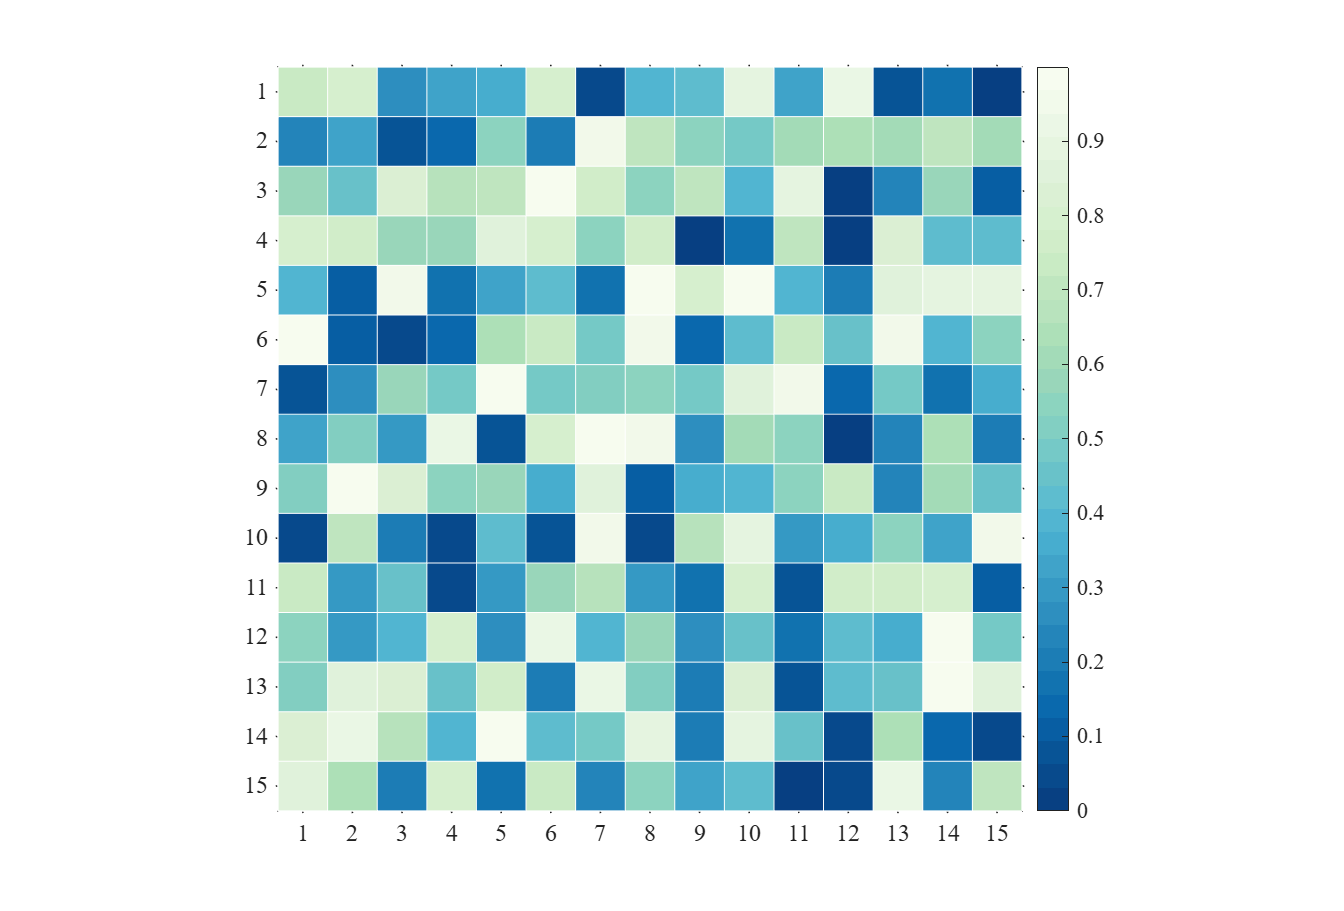

figure()
Data=rand(15,15);
SHM1=SHeatmap(Data,'Format','sq');
SHM1.draw();

### 1.2 Contains negative numbers (绘制有负数热图)

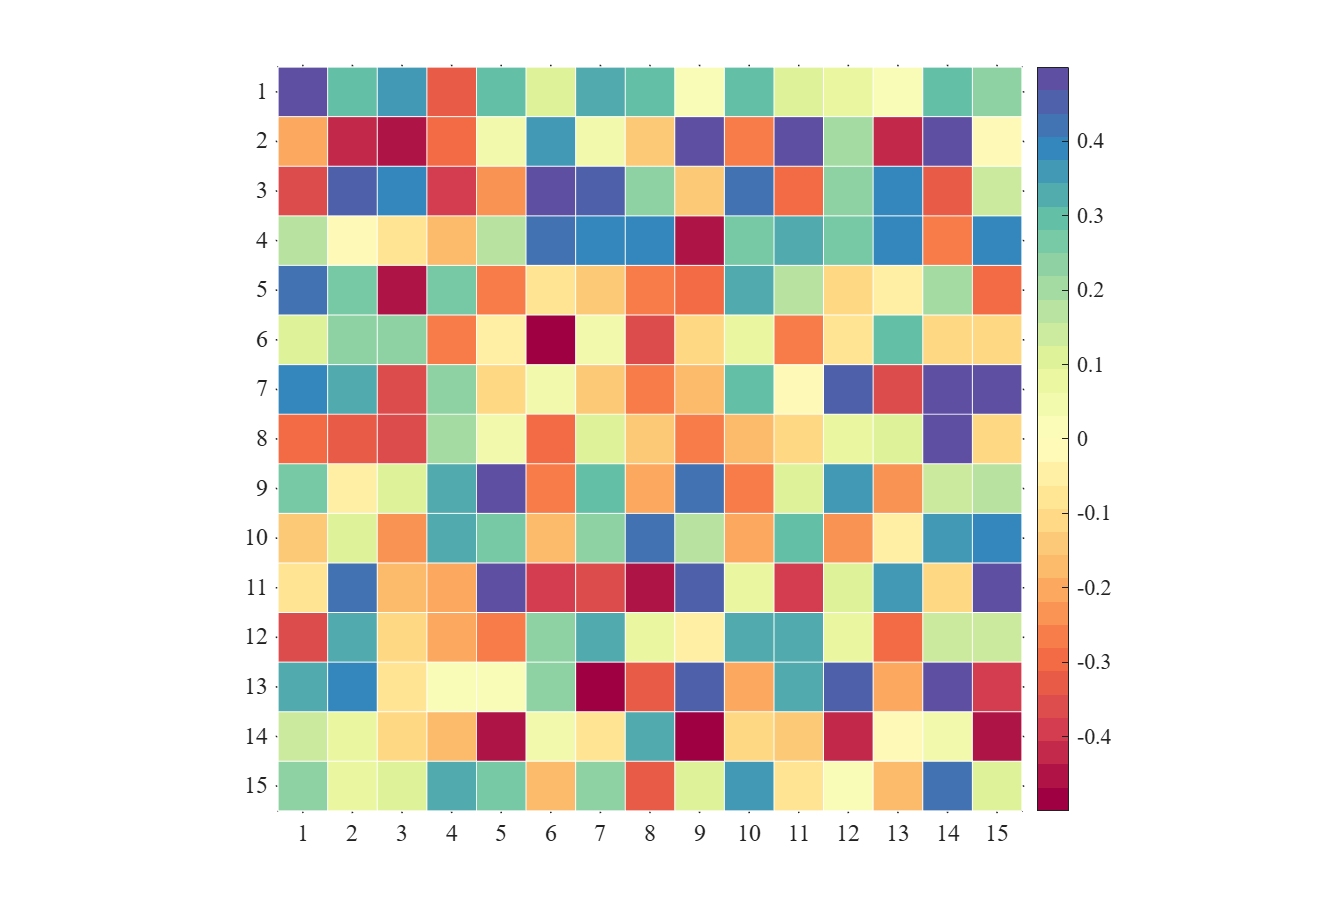

figure()
Data=rand(15,15)-.5;
SHM2=SHeatmap(Data,'Format','sq');
SHM2.draw();

### 1.3 Draw heatmaps of different sizes (绘制不同大小热图)

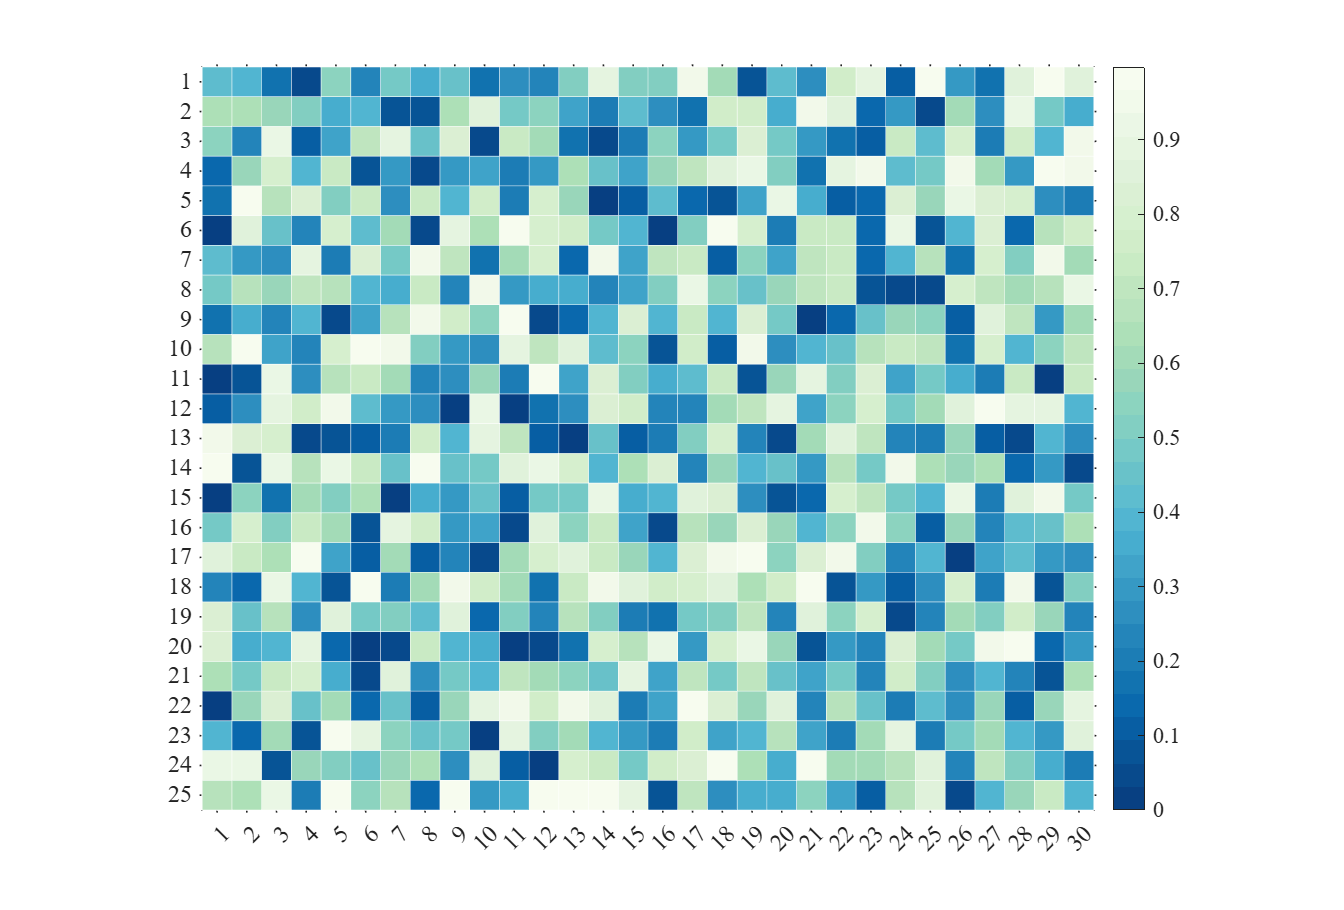

figure()
Data=rand(25,30);
SHM4=SHeatmap(Data,'Format','sq');
SHM4.draw();

### 1.4 Adjust the colorbar Location (调整colorbar位置)

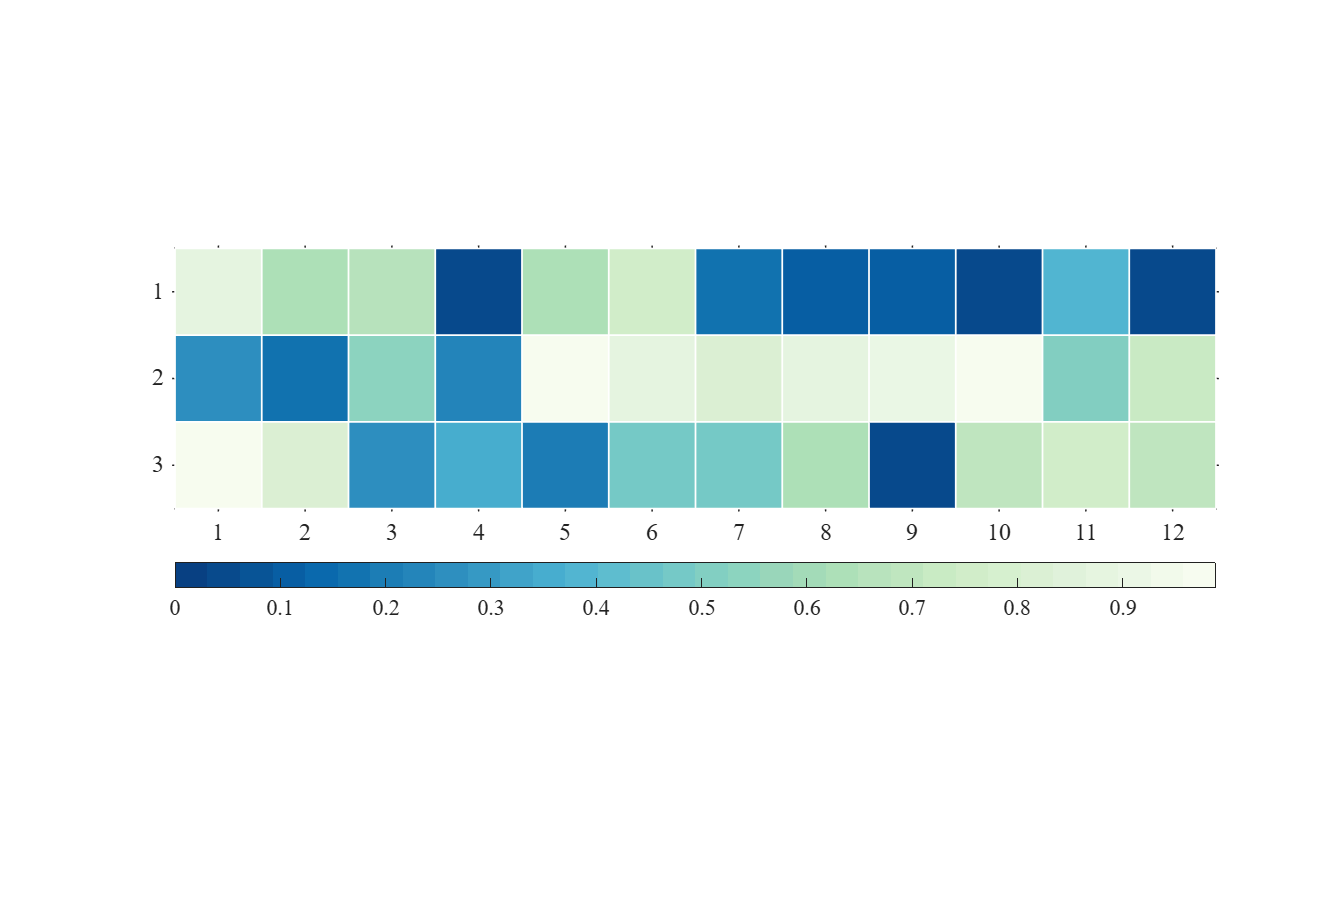

figure()
Data=rand(3,12);
SHM5=SHeatmap(Data,'Format','sq');
SHM5.draw();
CB=colorbar;
CB.Location='southoutside';

### 1.5 Draw heat map with NaN (绘制有NaN热图)

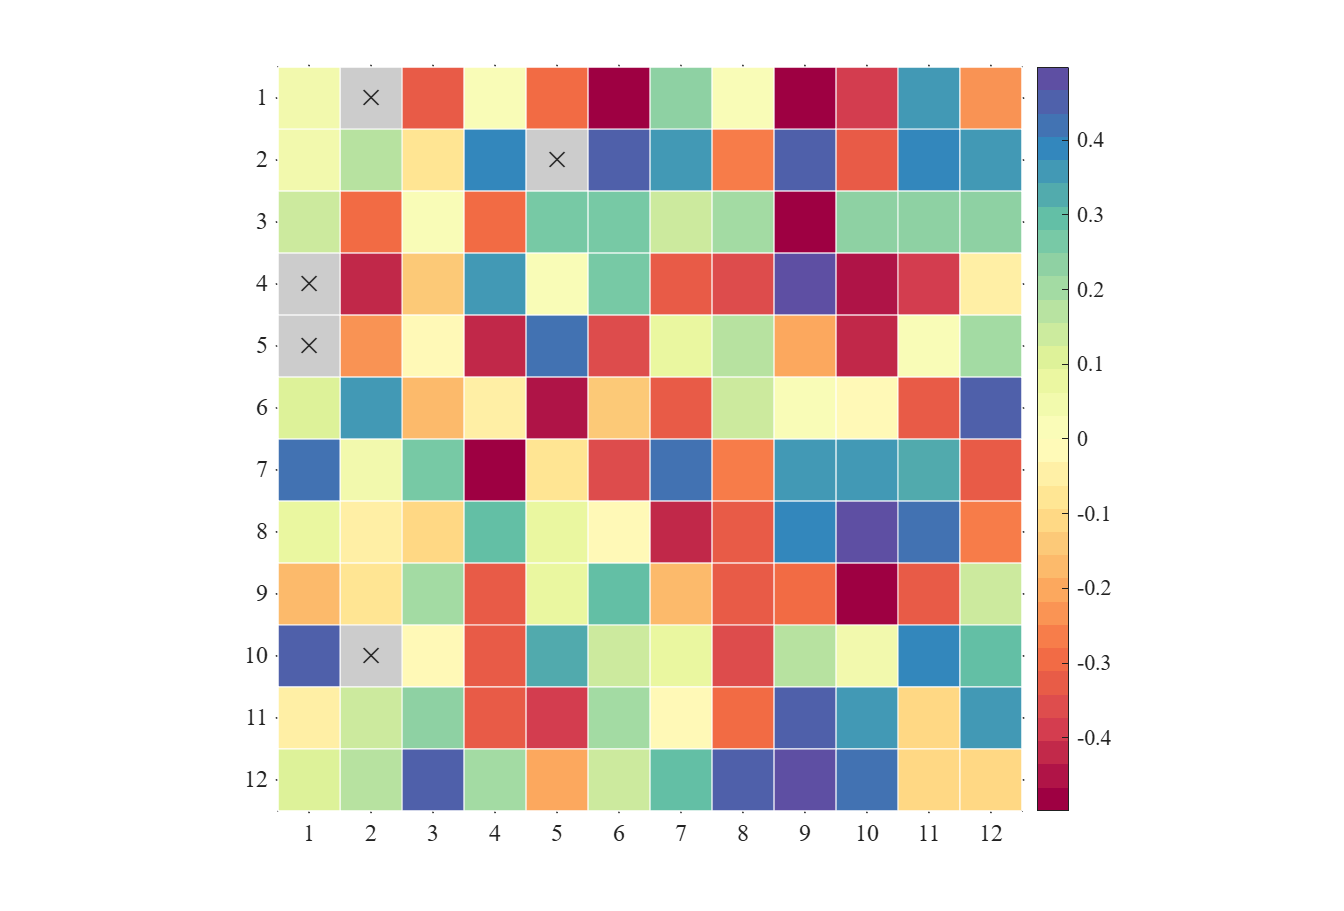

figure()
Data=rand(12,12)-.5;
Data([4,5,13,50,22])=nan;
SHM6=SHeatmap(Data,'Format','sq');
SHM6=SHM6.draw();

### 1.6 Draw heat map with value text (绘制有文本热图)

Use the ***setText()*** method to display value text:

使用 ***setText() ***方法显示文字：

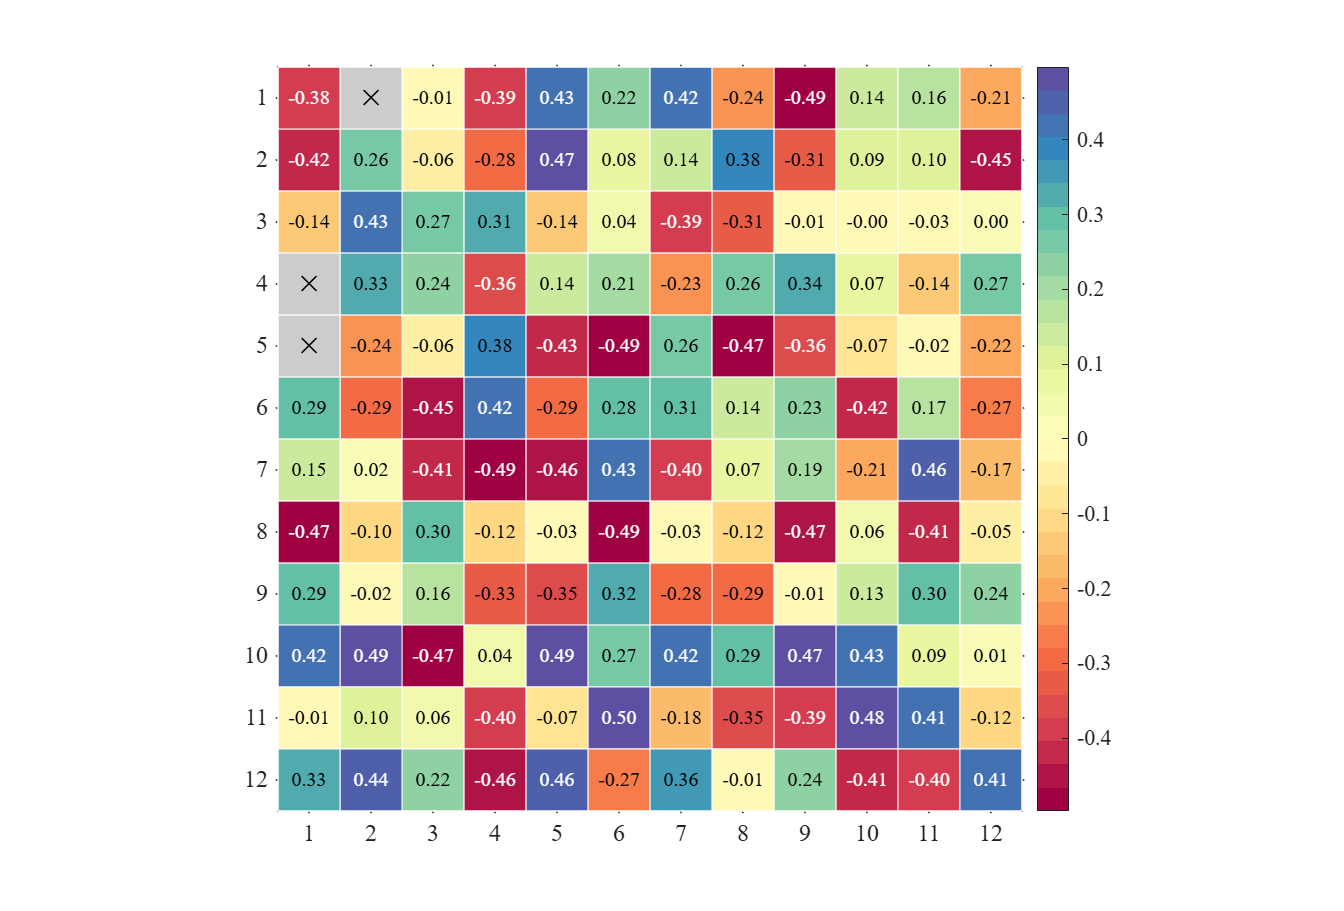

figure()
Data=rand(12,12)-.5;
Data([4,5,13])=nan;
SHM7=SHeatmap(Data,'Format','sq');
SHM7=SHM7.draw();
SHM7.setText();

### 1.7 Draw heatmap with labels (绘制带标签热图)

Change the x-axis and y-axis labels by setting ***XTickLabel*** and ***YTickLabel*** :

改 x-轴 y-轴标签就还是设置 ***XTickLabe***l 和 ***YTickLabel*** :

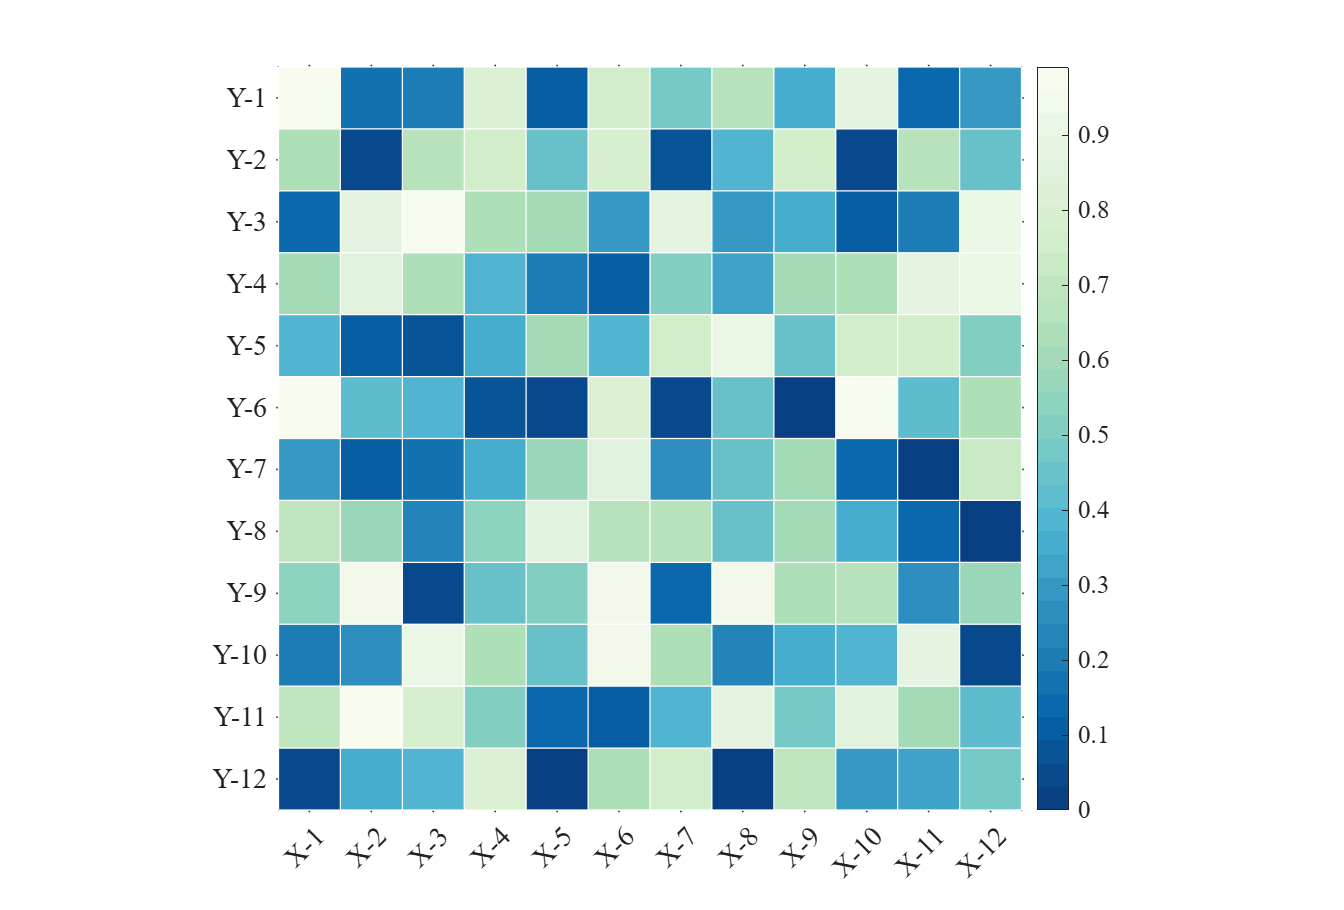

figure()
Data=rand(12,12);
SHM8=SHeatmap(Data,'Format','sq');
SHM8=SHM8.draw(); 
ax=gca;
ax.XTickLabel={'X-1','X-2','X-3','X-4','X-5','X-6','X-7','X-8','X-9','X-10','X-11','X-12'};
ax.YTickLabel={'Y-1','Y-2','Y-3','Y-4','Y-5','Y-6','Y-7','Y-8','Y-9','Y-10','Y-11','Y-12'};
ax.FontSize=14;

## 2 Various Format of heatmaps (各类型热图绘制)

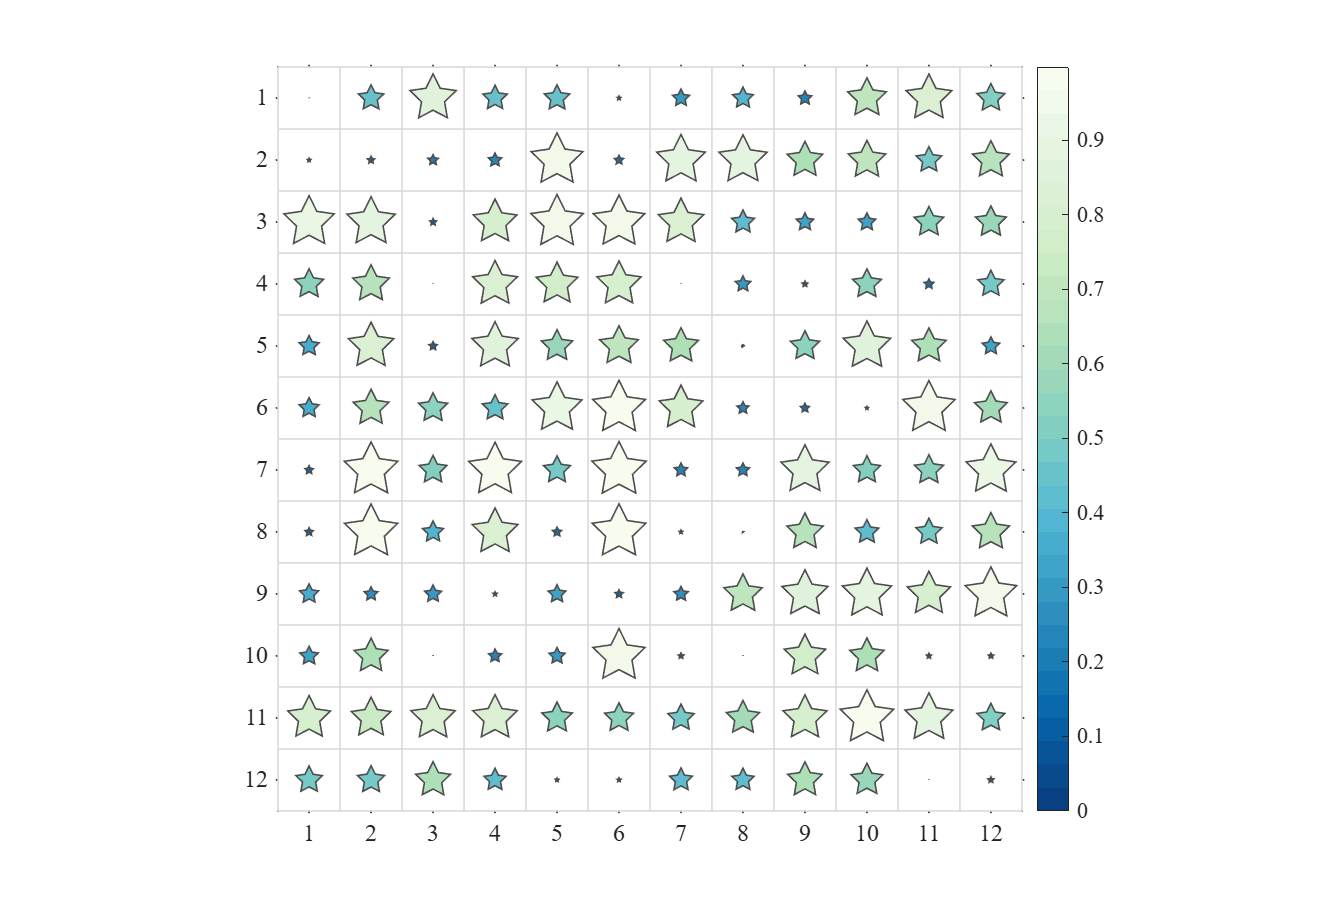

% 'sq'          : square (default)          : 方形(默认)
% 'pie'         : pie chart                 : 饼图
% 'donut'       ：donut chart               : 环形饼图(甜甜圈图)
% 'circ'        : circular                  : 圆形
% 'bcirc'       : circle with box           : 有边框的圆形
% 'oval'        : oval                      : 椭圆形
% 'hex'         : hexagon                   ：六边形
% 'star'        : star                      : 五角星
% 'trill'(tril) : lower left triangle       : 下三角
% 'triur'(triu) : upper right triangle      : 上三角
% 'trilr'       : lower right triangle      : 右下三角
% 'triul'       : upper left triangle       : 左上三角
% 'asq'         : auto-size square          ：自带调整大小的方形
% 'acirc'       : auto-size circular        ：自带调整大小的圆形

A=rand(12,12);
B=rand(12,12)-.5;


% 绘制纯正数热图(Draw positive heat map)
figure();
SHM_A=SHeatmap(A,'Format','star');
SHM_A=SHM_A.draw();
% 绘制含负数热图(Draw heat map with negative number)

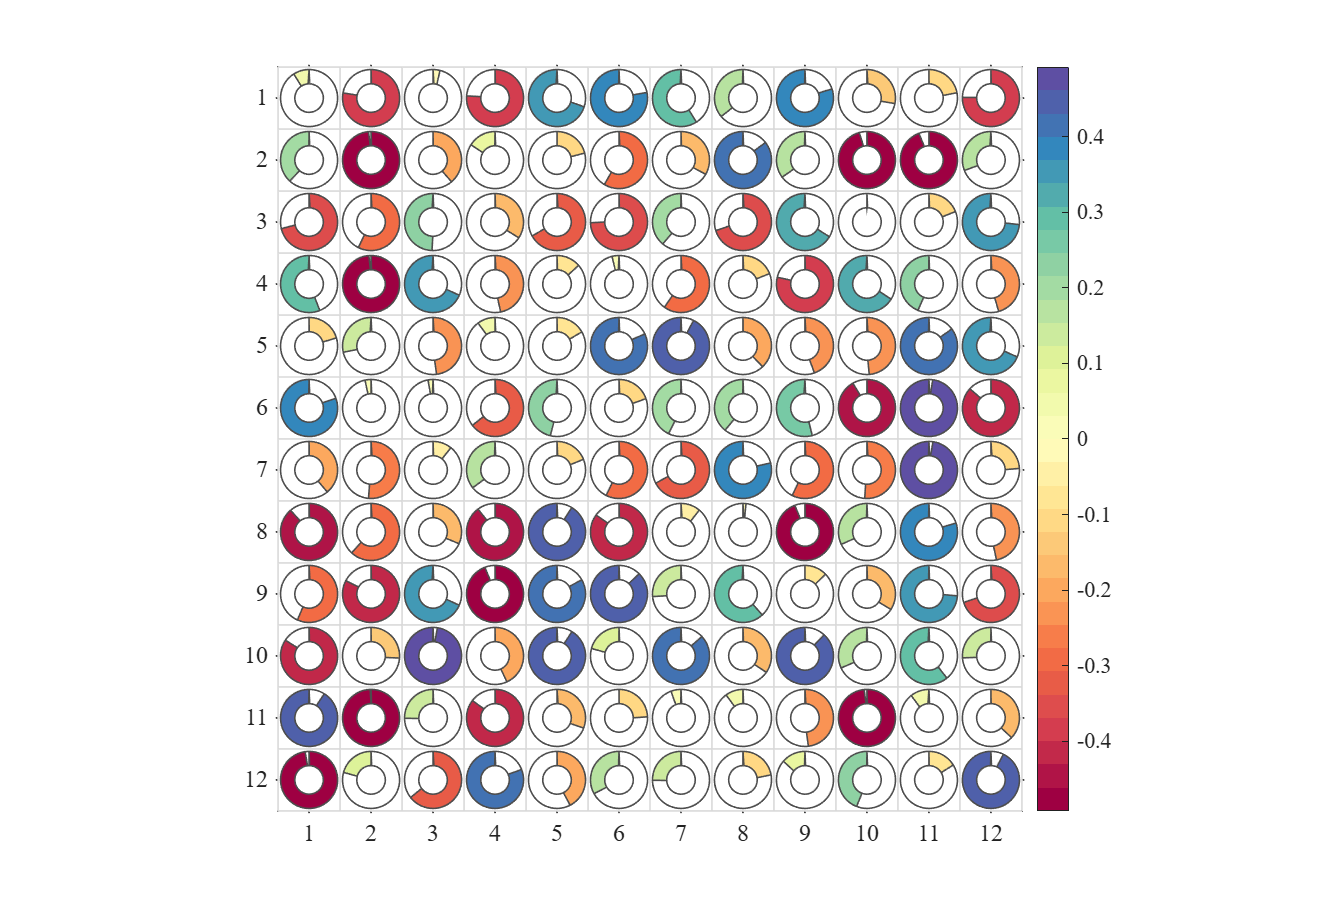

figure();
SHM_B=SHeatmap(B,'Format','donut');
SHM_B=SHM_B.draw();

### 2.2 Custom shape and auto-size custom shape (自定义形状)

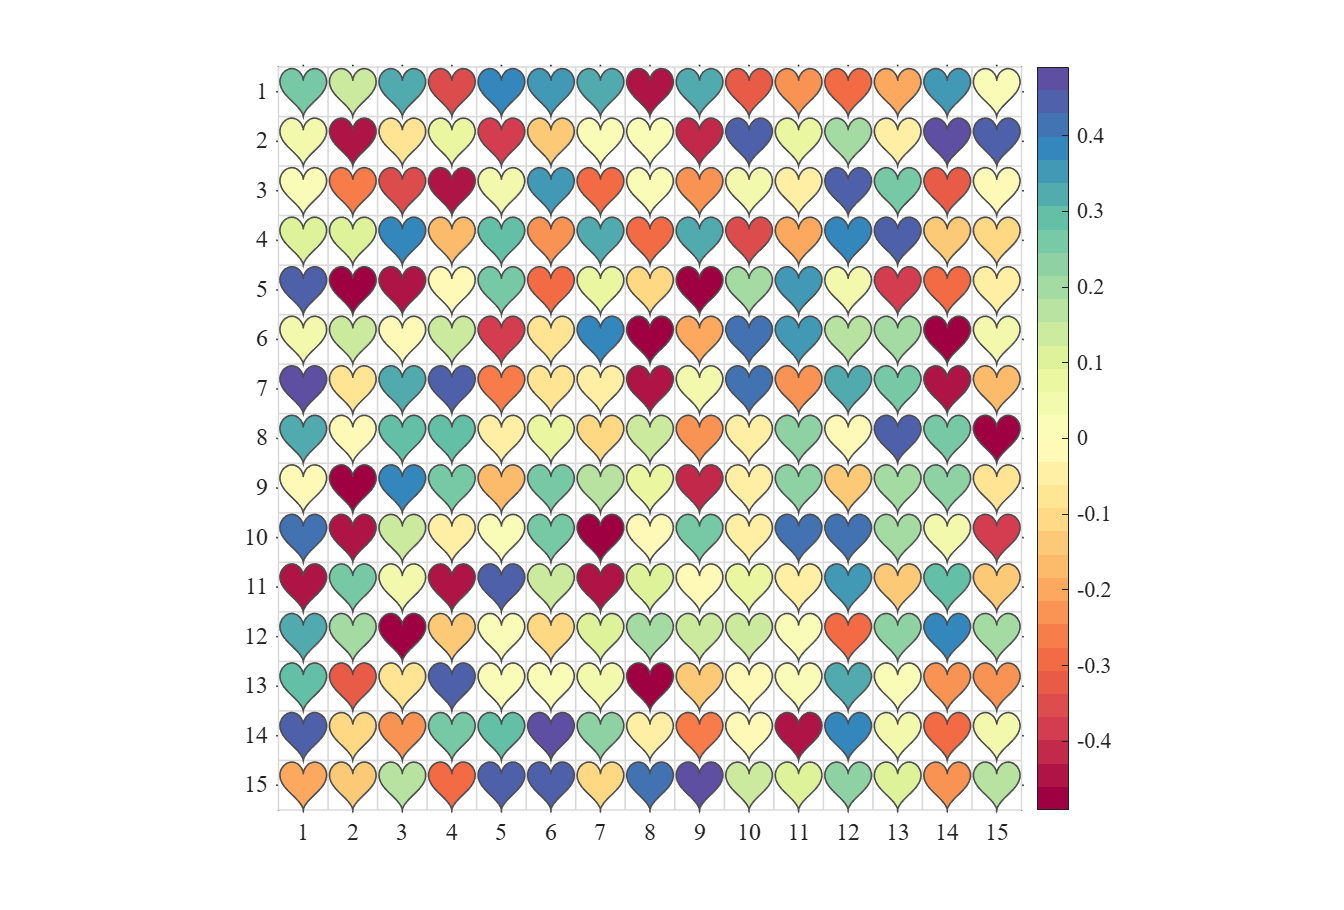

% The shape need to be in range in X:[-.5,.5], Y:[-.5,.5]; 
% The 'SData' need to be set.

% heart shape
t = linspace(0, 2*pi, 200);
x = 16*sin(t).^3./34;
y = (13*cos(t) - 5*cos(2*t) - 2*cos(3*t) - cos(4*t) + 2.1)./30;
SData = [x;y];

% custom shape
figure()
Data=rand(15,15)-.5;
SHM1=SHeatmap(Data,'Format','cust','SData',SData);
SHM1.draw();
% auto-size custom shape

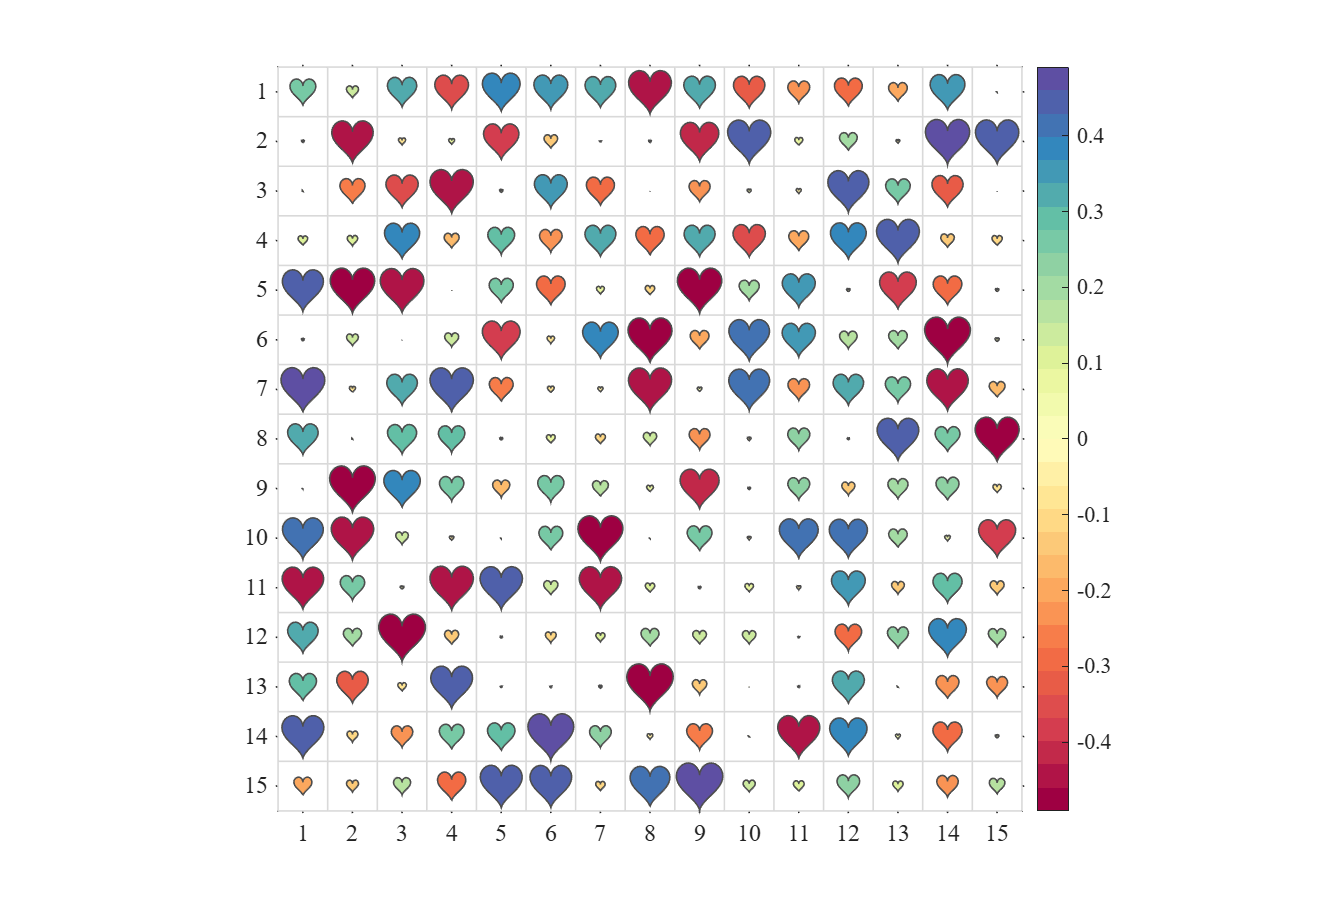

figure()
SHM2=SHeatmap(Data,'Format','acust','SData',SData);
SHM2.draw();

## 3 Adjust colormap (调整 colormap)

### 3.1 Adjust clim (调整 clim)

使用 ***clim()*** 或者 ***caxis()*** 调整颜色映射范围

Use function ***clim()*** or ***caxis()*** to set the CLim

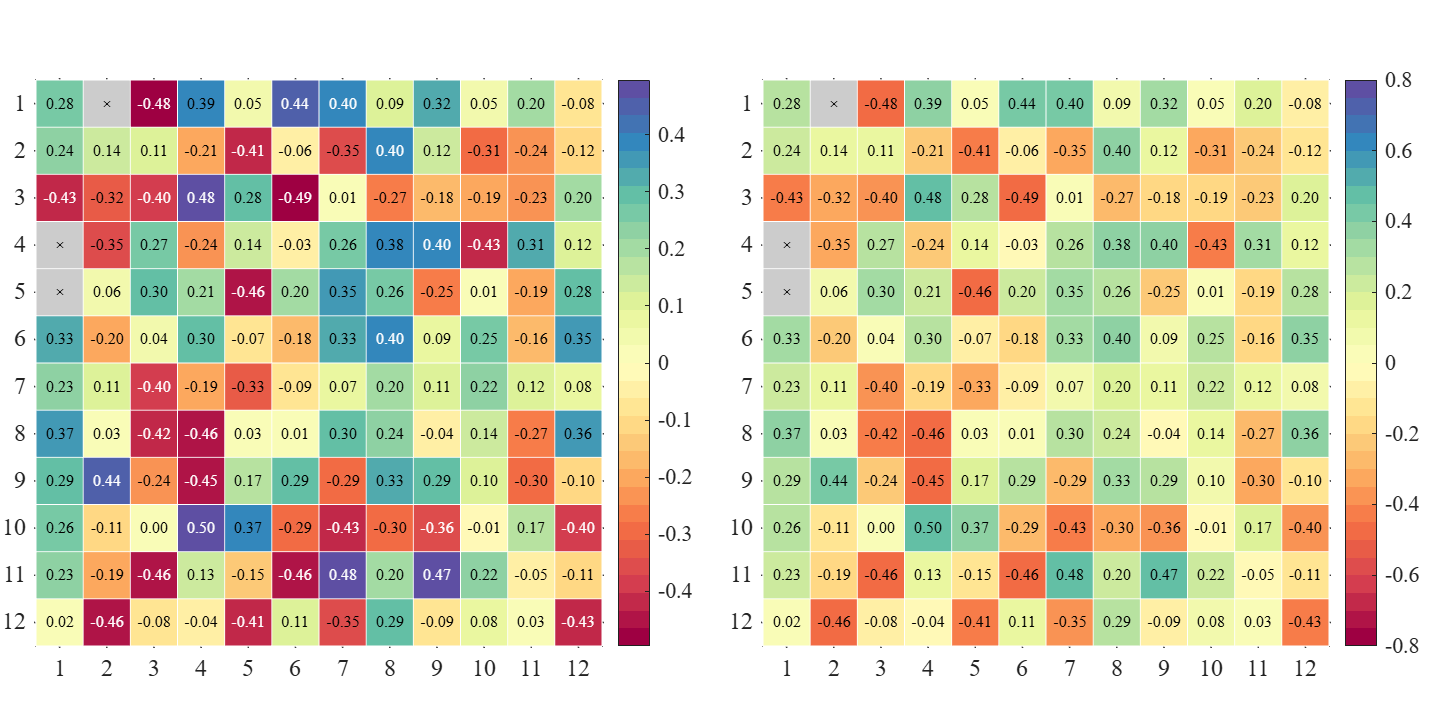

fig=figure('Position',[50,50,1400,700]);
% random data
Data=rand(12,12)-.5;
Data([4,5,13])=nan;
% subplot1
ax1=axes('Parent',fig,'Position',[0+1/40,0,1/2-1/20,1]);
SHM_ax1=SHeatmap(Data,'Format','sq','Parent',ax1);
SHM_ax1=SHM_ax1.draw();
SHM_ax1.setText('FontSize',8);
% subplot2 adjust clim
ax2=axes('Parent',fig,'Position',[1/2+1/40,0,1/2-1/20,1]);
SHM_ax2=SHeatmap(Data,'Format','sq','Parent',ax2);
SHM_ax2=SHM_ax2.draw();
clim([-.8,.8])
SHM_ax2.setText('FontSize',8);

### 3.2 Use the built-in colormap in MATLAB (使用MATLAB自带colormap)

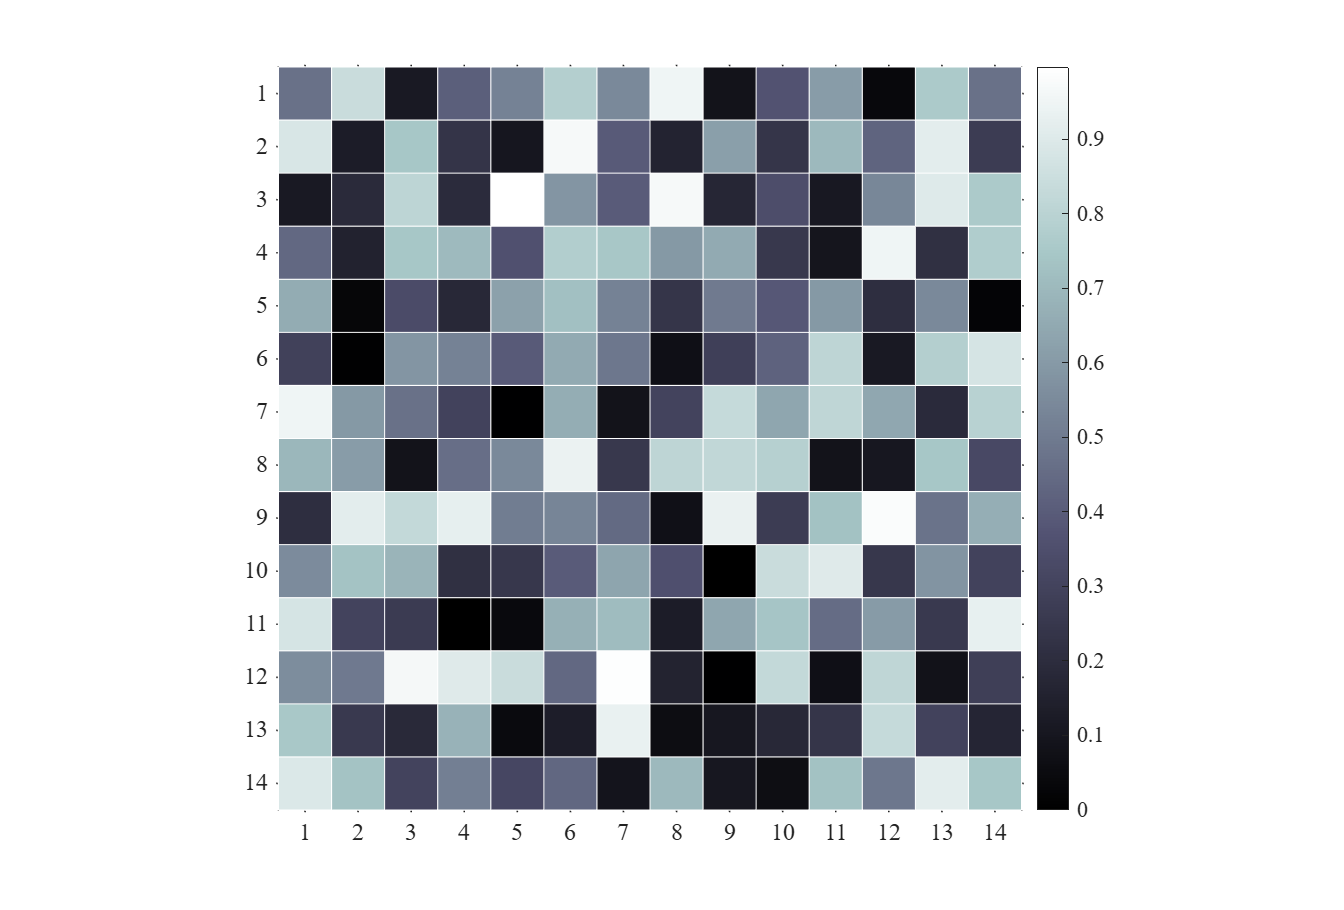

figure()
Data=rand(14,14);
SHM_Bone=SHeatmap(Data,'Format','sq');
SHM_Bone.draw();
colormap(bone)

### 3.3 slanCM (slanCM colormap)

Zhaoxu Liu / slandarer (2023). 200 colormap (https://www.mathworks.com/matlabcentral/fileexchange/120088-200-colormap), MATLAB Central File Exchange. 检索来源 2023/3/15.

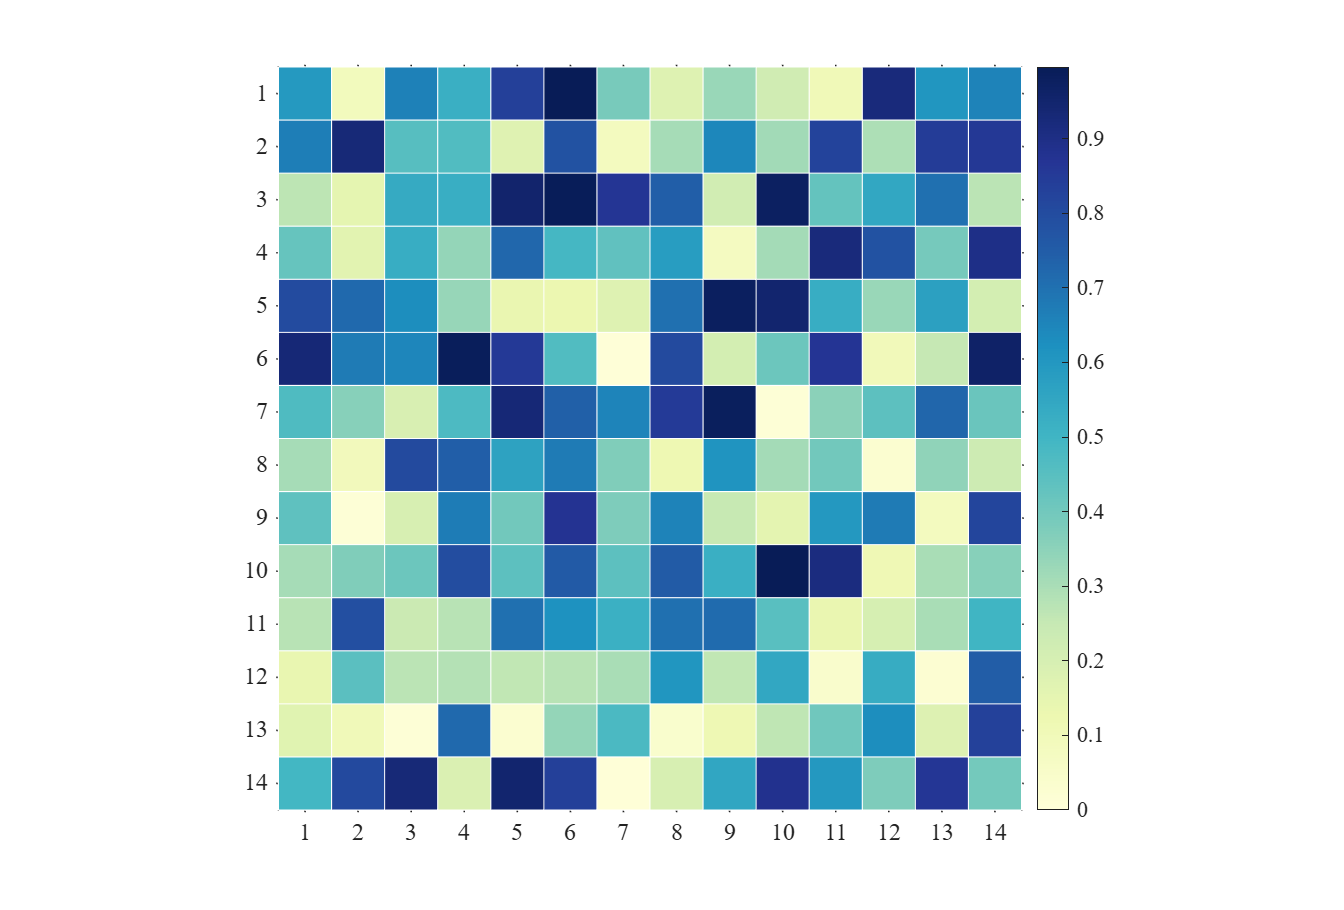

% 单向colormap或离散colormap
for i = 21 %[20,21,61,177]
    figure()
    Data=rand(14,14);
    SHM_slan=SHeatmap(Data,'Format','sq');
    SHM_slan.draw();
    colormap(slanCM(i))
end
% 双向colormap(Diverging colormap)
for i=[141,136] % 134

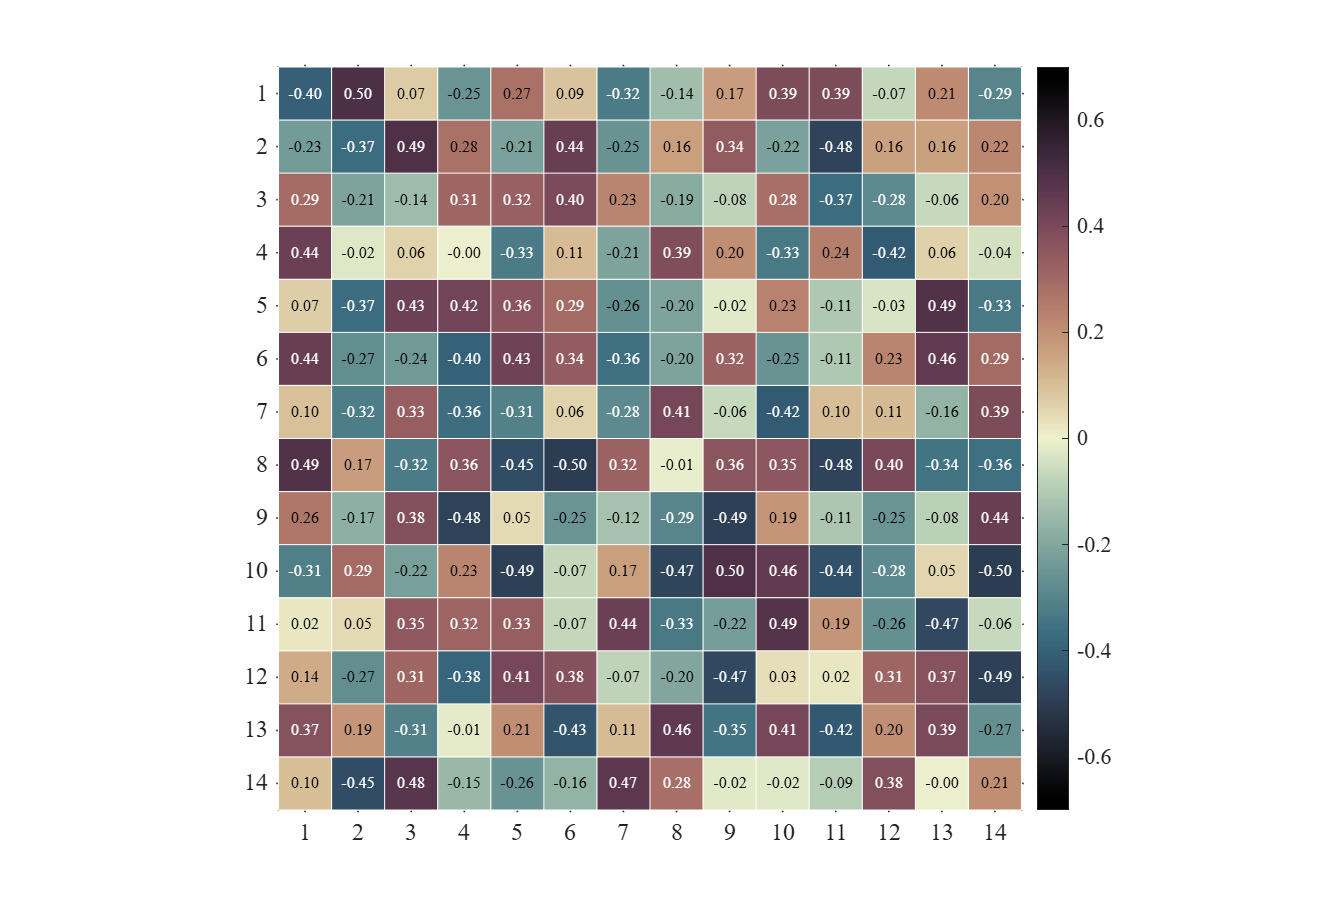

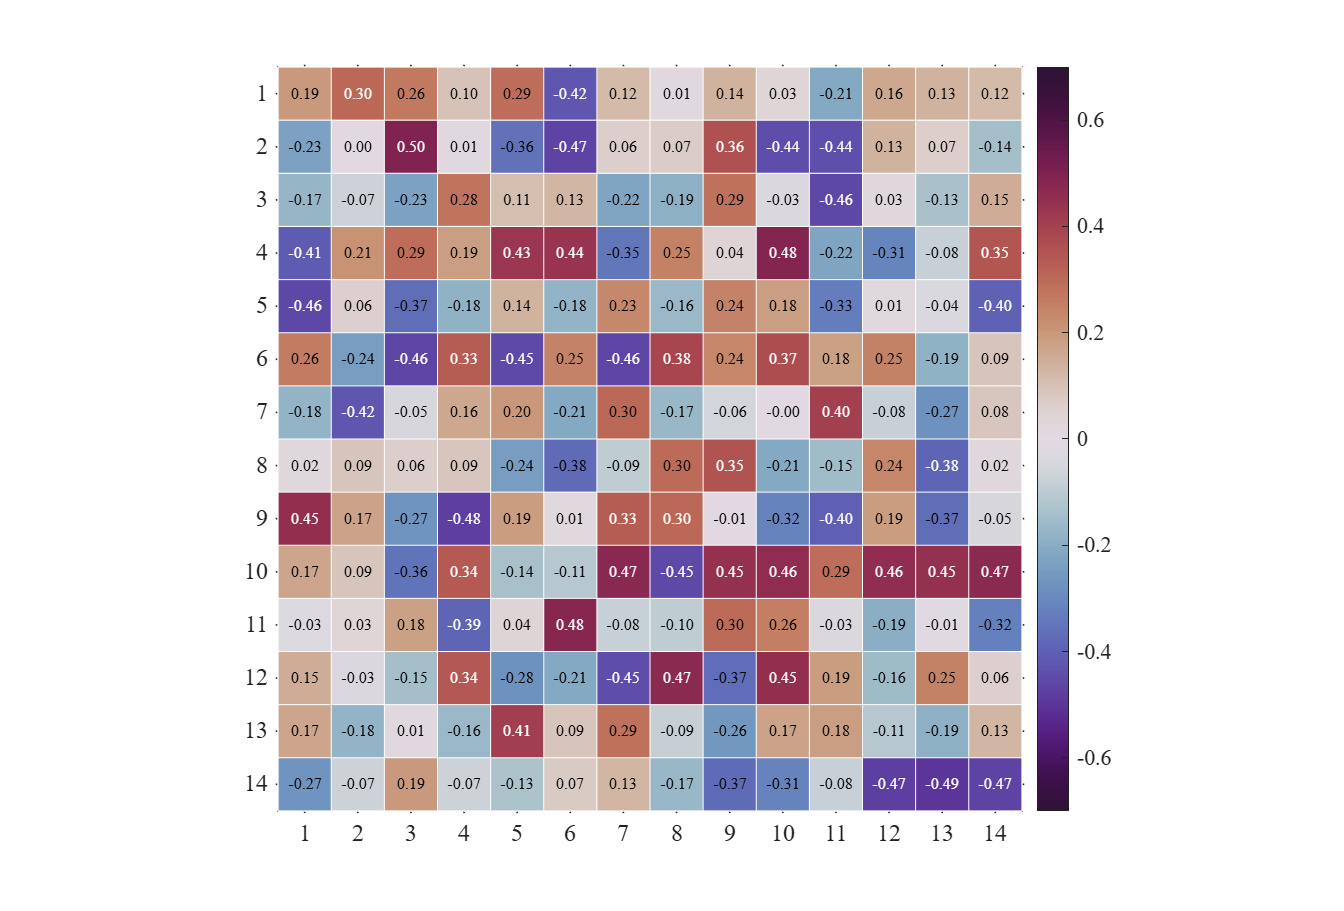

    figure()
    Data=rand(14,14)-.5;
    SHM_slan=SHeatmap(Data,'Format','sq');
    SHM_slan=SHM_slan.draw();
    clim([-.7,.7])
    colormap(slanCM(i))
    SHM_slan.setText('FontSize',8);
end

## 4 Overall decoration (整体修饰)

- setBox   ：修饰边框

- setPatch ：修饰图形

- setText  ：修饰文本

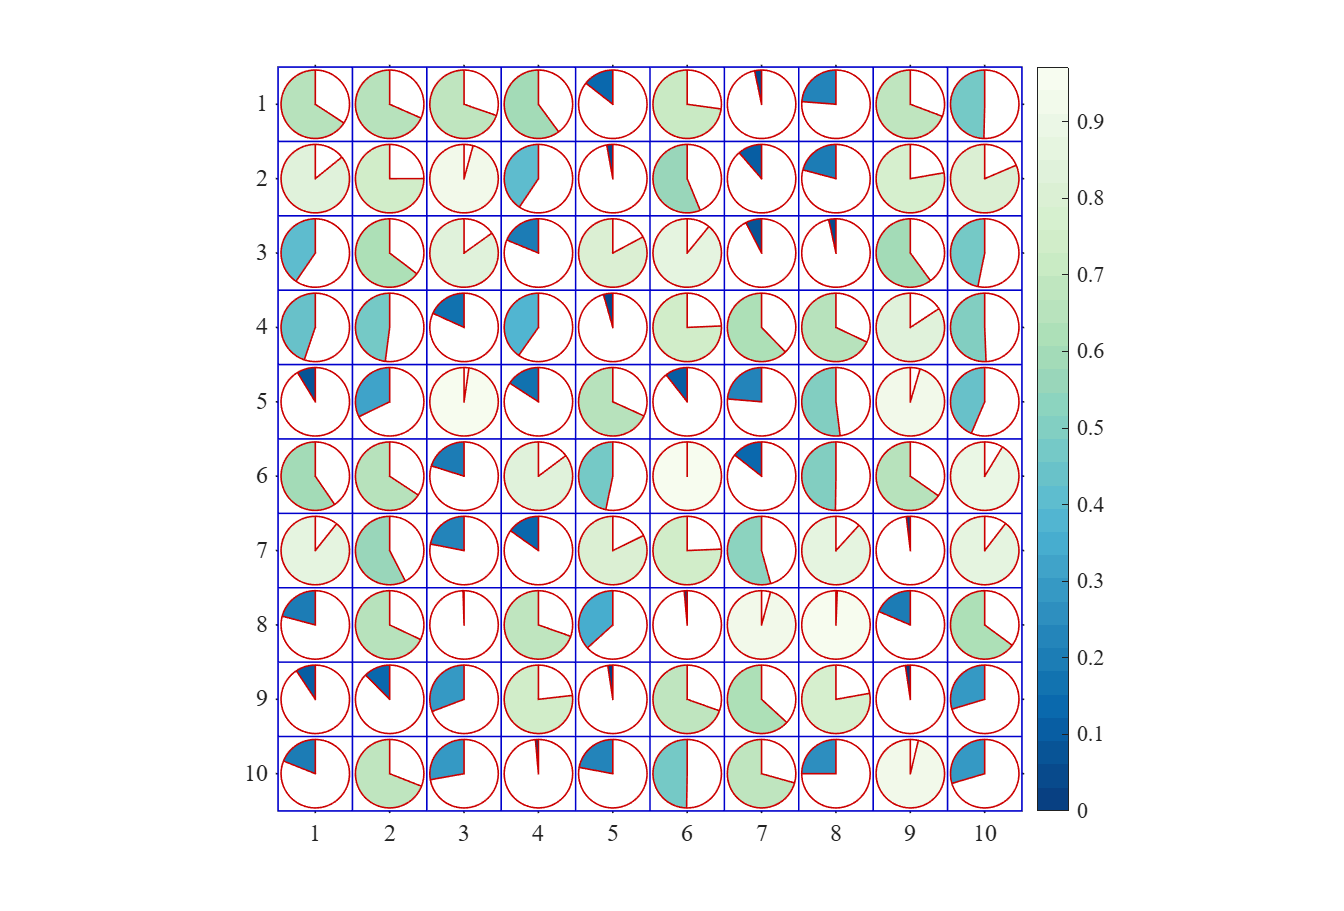

figure()
Data=rand(10,10);

SHM=SHeatmap(Data,'Format','pie');
SHM=SHM.draw(); 
% 容器边框设置为蓝色
% 图形边框设置为红色
% The container box border is set to blue
% The drawing border is set to red
SHM.setBox('Color',[0,0,.8])
SHM.setPatch('EdgeColor',[.8,0,0])

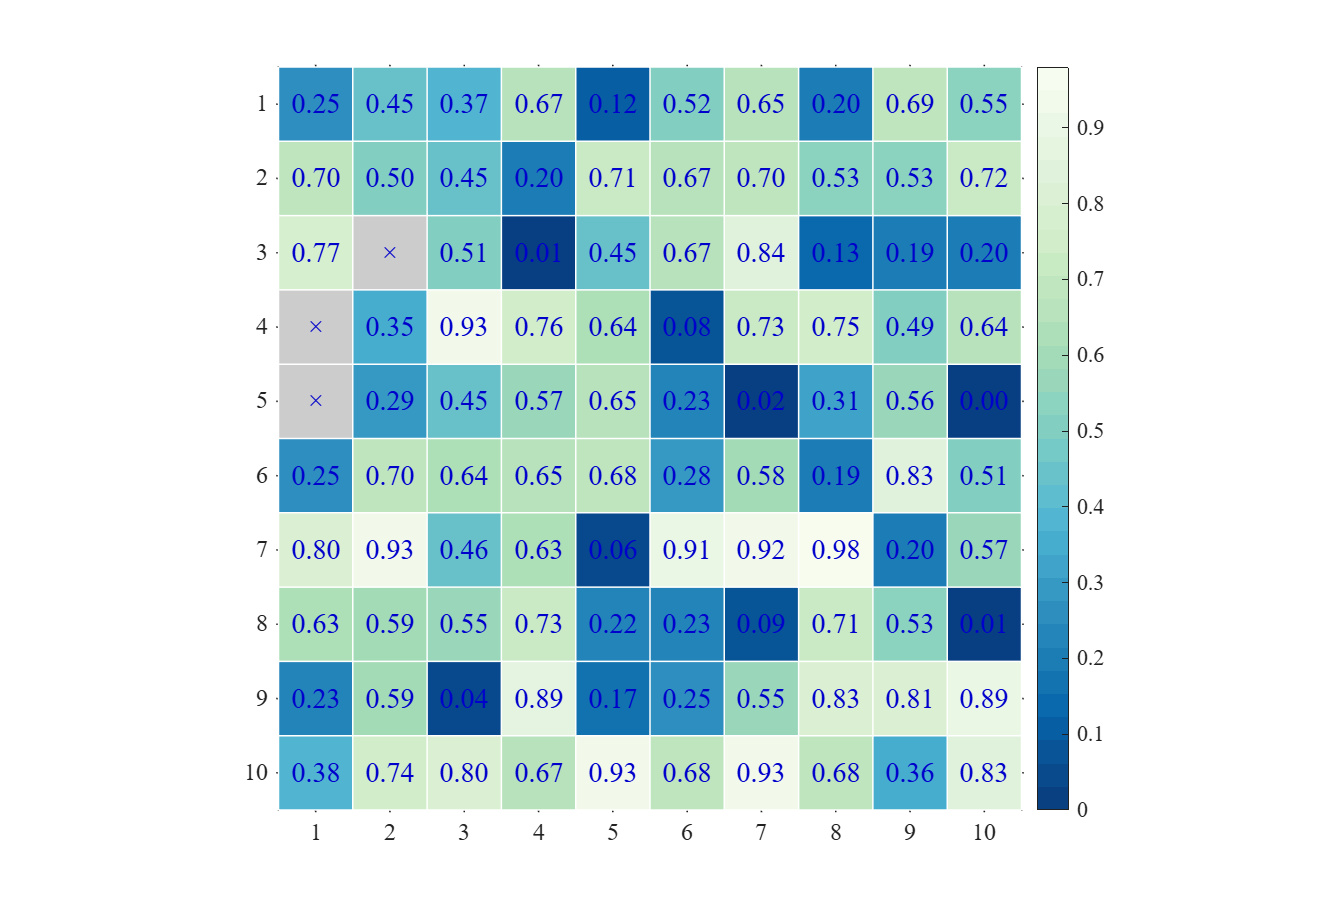

figure()
Data=rand(10,10);
Data([4,5,13])=nan;

SHM=SHeatmap(Data,'Format','sq');
SHM=SHM.draw(); 
% 设置文本为蓝色并修改字号
% Set the text to blue and modify the font size
SHM.setText('Color',[0,0,.8],'FontSize',14)

## 5 Partial decoration (局部修饰)

- setTextMN

- setPatchMN

Set the attributes of the object in row m and column n: for example, change the text with a value greater than 0.9 into an asterisk, frame it in red, and adapt the color at NaN.

设置第 m 行 n 列对象的属性：举个例子，把数值大于0.9部分文字变为星号，并用红色框框起来，并改编NaN处颜色。

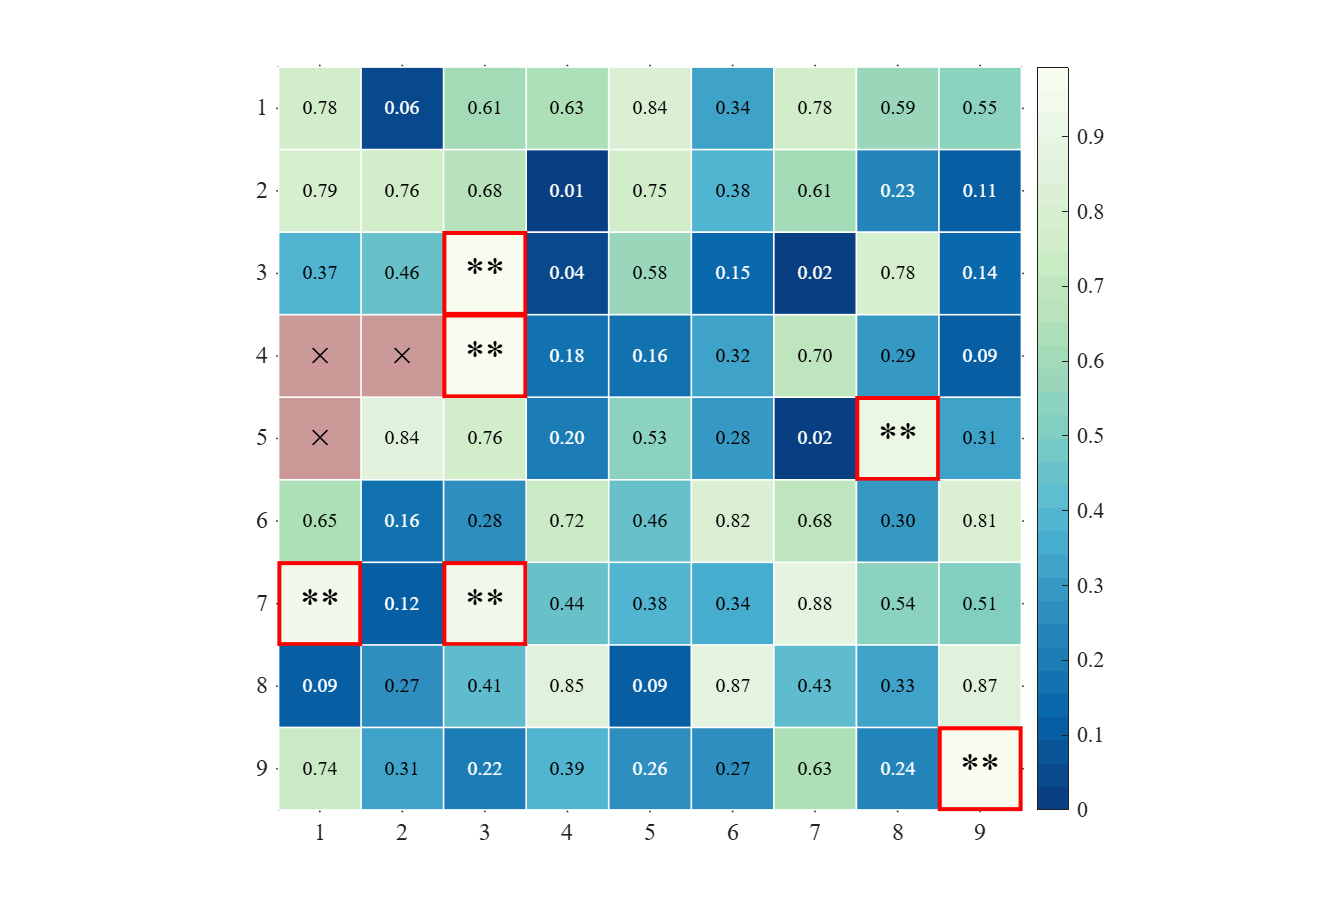

figure()
Data=rand(9,9);
Data([4,5,13])=nan;
% 绘制方块形状热图
SHM=SHeatmap(Data,'Format','sq');
SHM=SHM.draw();
% 显示文本(Show Text)
SHM.setText(); 
for i=1:size(Data,1)
    for j=1:size(Data,2)
        if Data(i,j)>=.9
            SHM.setTextMN(i,j,'String','**','FontSize',20)         % 修改>=0.9方块颜色
            SHM.setPatchMN(i,j,'EdgeColor',[1,0,0],'LineWidth',2)  % 修改>=0.9方块文本为**
        end
        if isnan(Data(i,j))
            SHM.setPatchMN(i,j,'FaceColor',[.8,.6,.6]) % 修改NaN处颜色
        end
    end

end

## 6 Set to upper triangle or lower triangle (设置为上三角或下三角)

### 6.1 upper triangle or lower triangle (上下三角格式)

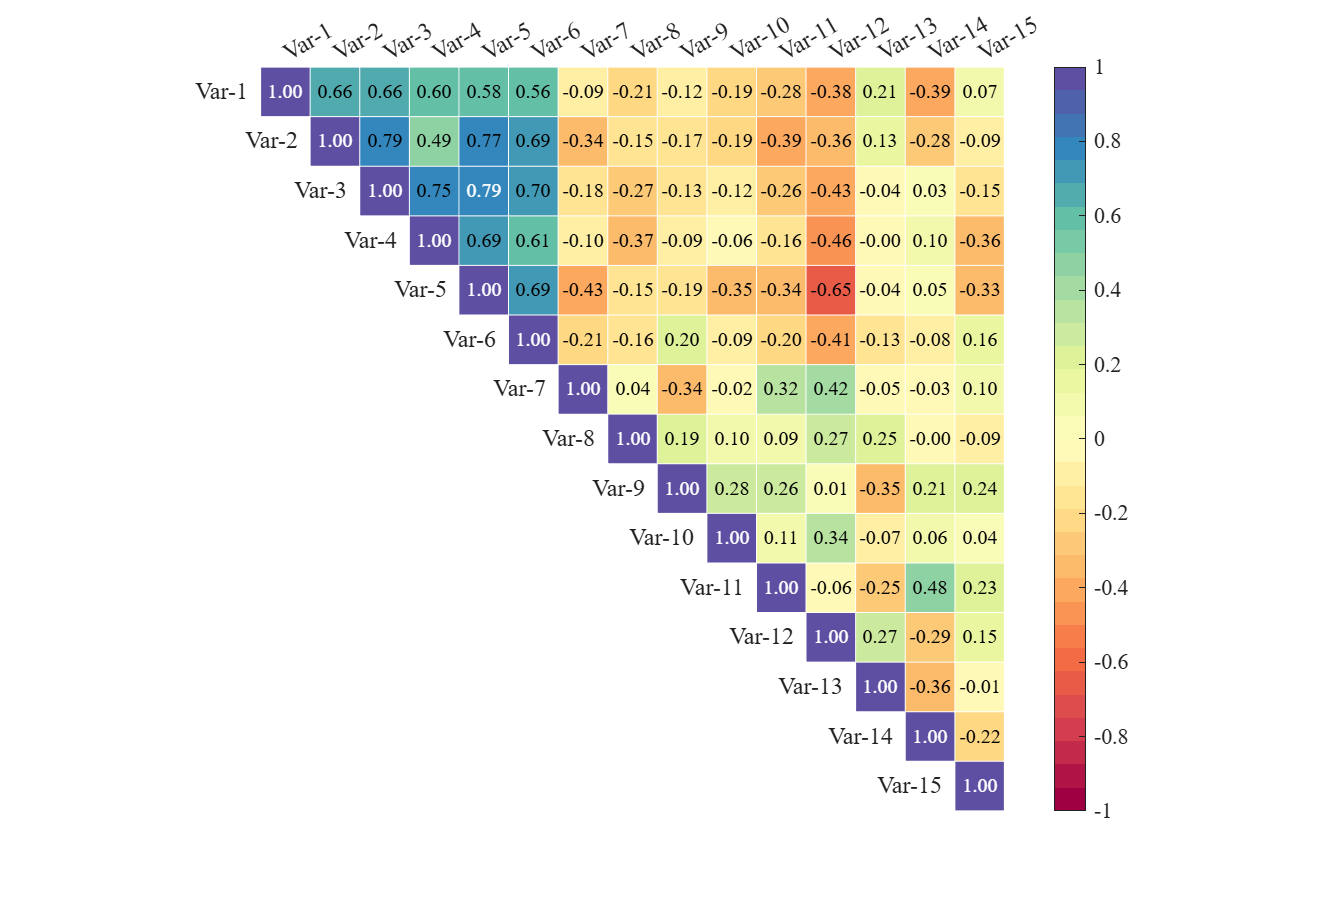

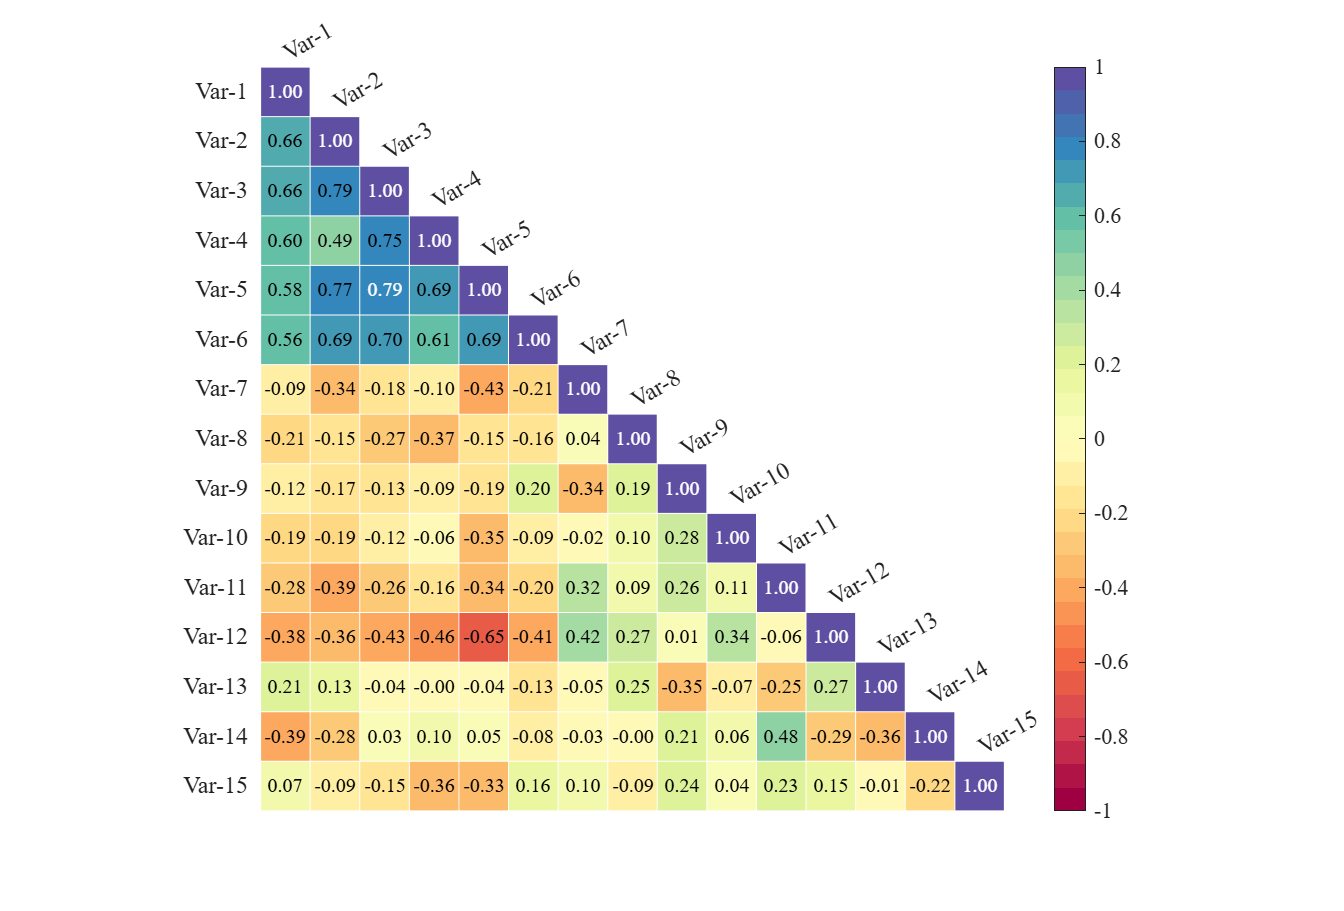

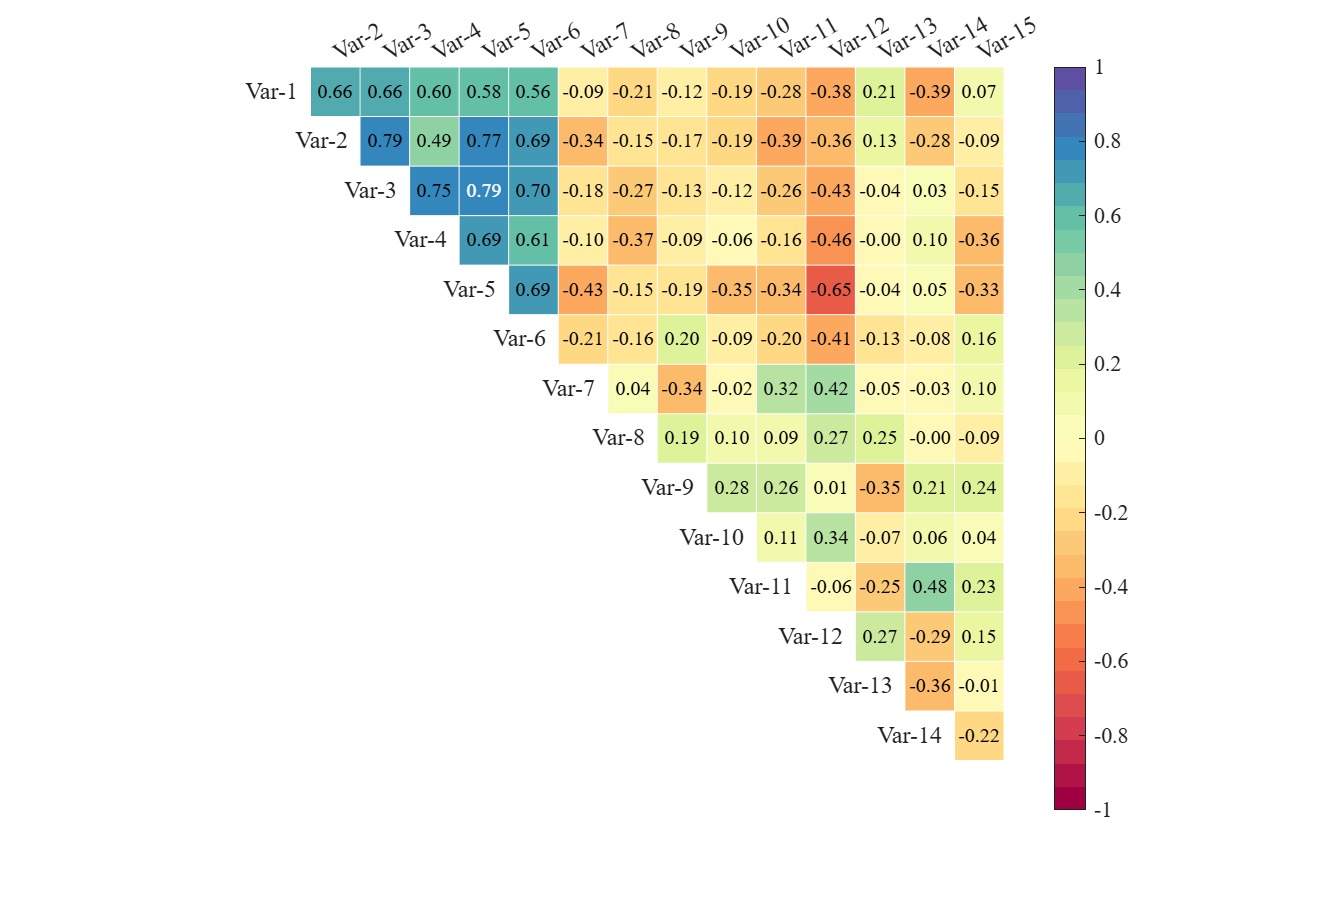

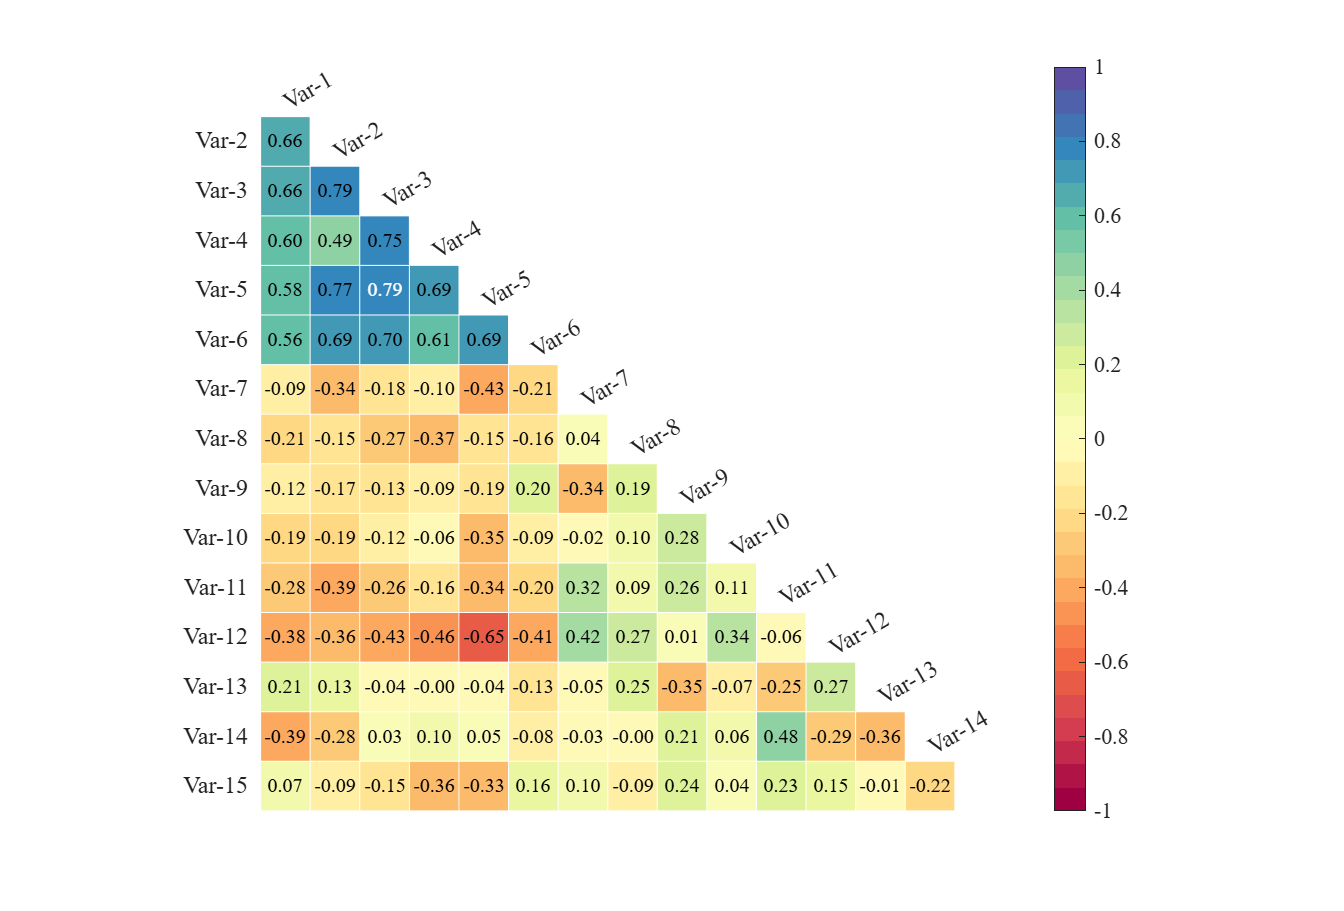

% Made up some data casually (随便捏造了点数据)
X=randn(20,15)+[(linspace(-1,2.5,20)').*ones(1,6),(linspace(.5,-.7,20)').*ones(1,5),(linspace(.9,-.2,20)').*ones(1,4)];
% Get the correlation matrix (求相关系数矩阵)
Data=corr(X);

% + 'triu'   : upper triangle                  : 上三角部分
% + 'tril'   : lower triangle                  : 下三角部分
% + 'triu0'  : upper triangle without diagonal : 扣除对角线上三角部分
% + 'tril0'  : lower triangle without diagonal : 扣除对角线下三角部分

Type={'triu','tril','triu0','tril0'};
for i=1:length(Type)
    figure()
    SHM_s1=SHeatmap(Data,'Format','sq');
    SHM_s1=SHM_s1.draw();
    SHM_s1.setText();
    % set Type (设置格式)
    SHM_s1.setType(Type{i});

end

### 6.2 Set variable labels' String (设置标签名称)

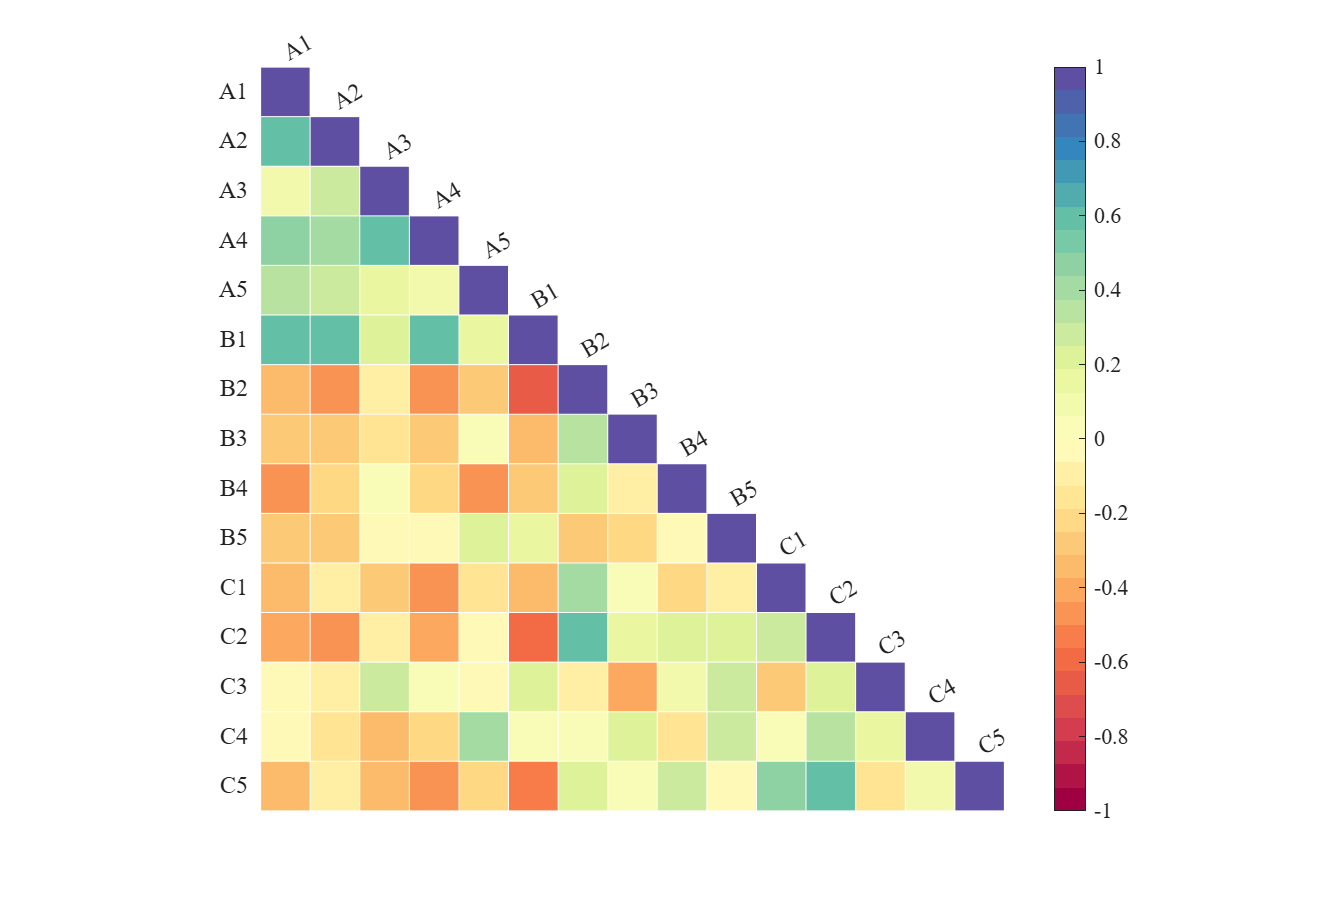

% Made up some data casually (随便捏造了点数据)
X=randn(20,15)+[(linspace(-1,2.5,20)').*ones(1,6),(linspace(.5,-.7,20)').*ones(1,5),(linspace(.9,-.2,20)').*ones(1,4)];
% Get the correlation matrix (求相关系数矩阵)
Data=corr(X);

figure()
SHM_s2=SHeatmap(Data,'Format','sq');
SHM_s2=SHM_s2.draw();
SHM_s2.setType('tril');

varName={'A1','A2','A3','A4','A5','B1','B2','B3','B4','B5','C1','C2','C3','C4','C5'};

SHM_s2.setVarName(varName)

### 6.3 Adjust the axis Limit to avoid occlusion (调整轴范围以避免遮挡)

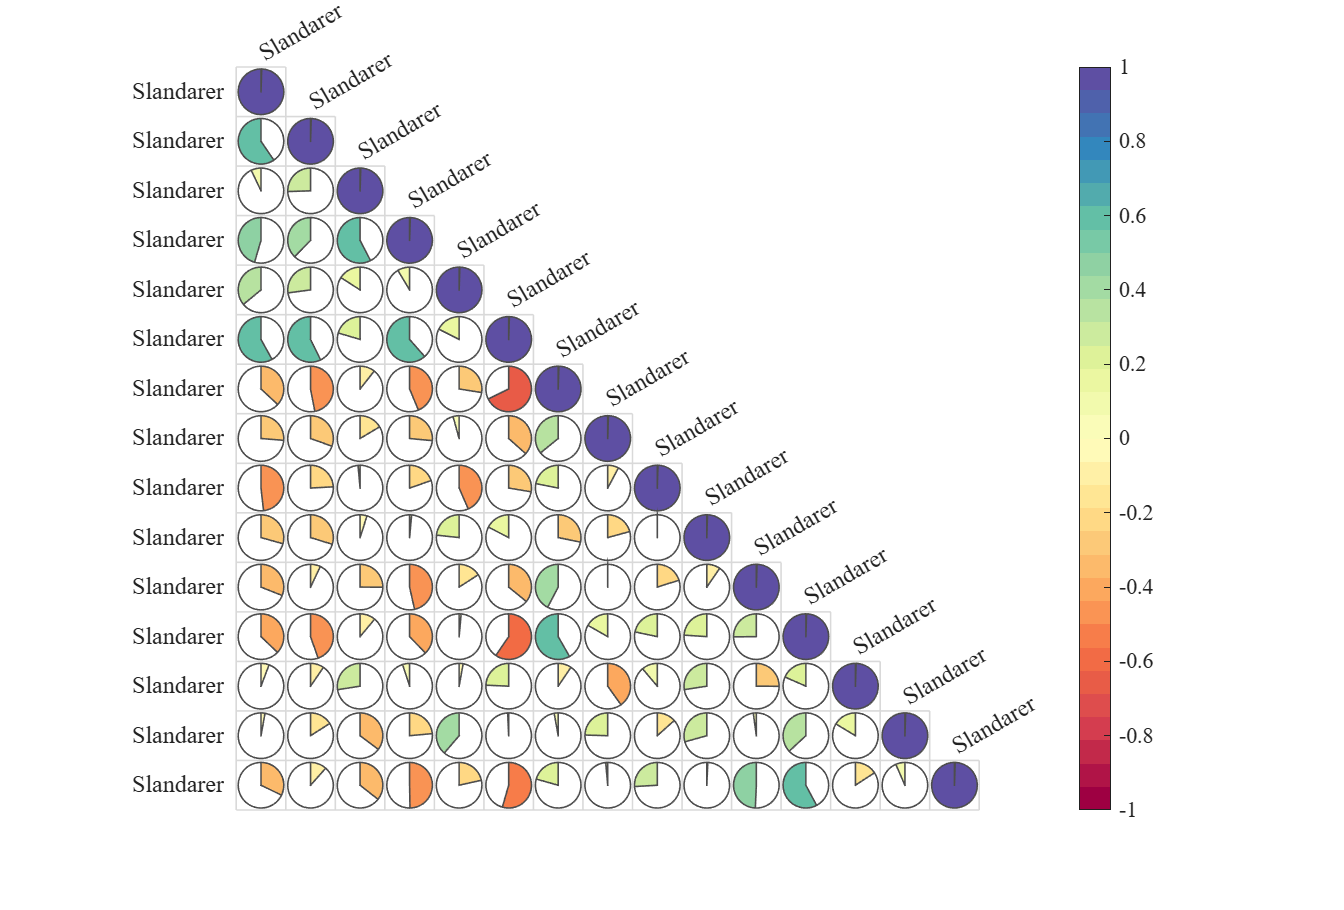

figure()
SHM_s3=SHeatmap(Data,'Format','pie');
SHM_s3=SHM_s3.draw();
SHM_s3.setType('tril');
SHM_s3.setVarName({'Slandarer'})
ax=gca;

ax.XLim(2)=ax.XLim(2)+1;

### 6.4 Show upper triangle of all formats (展示所有样式的上三角化)

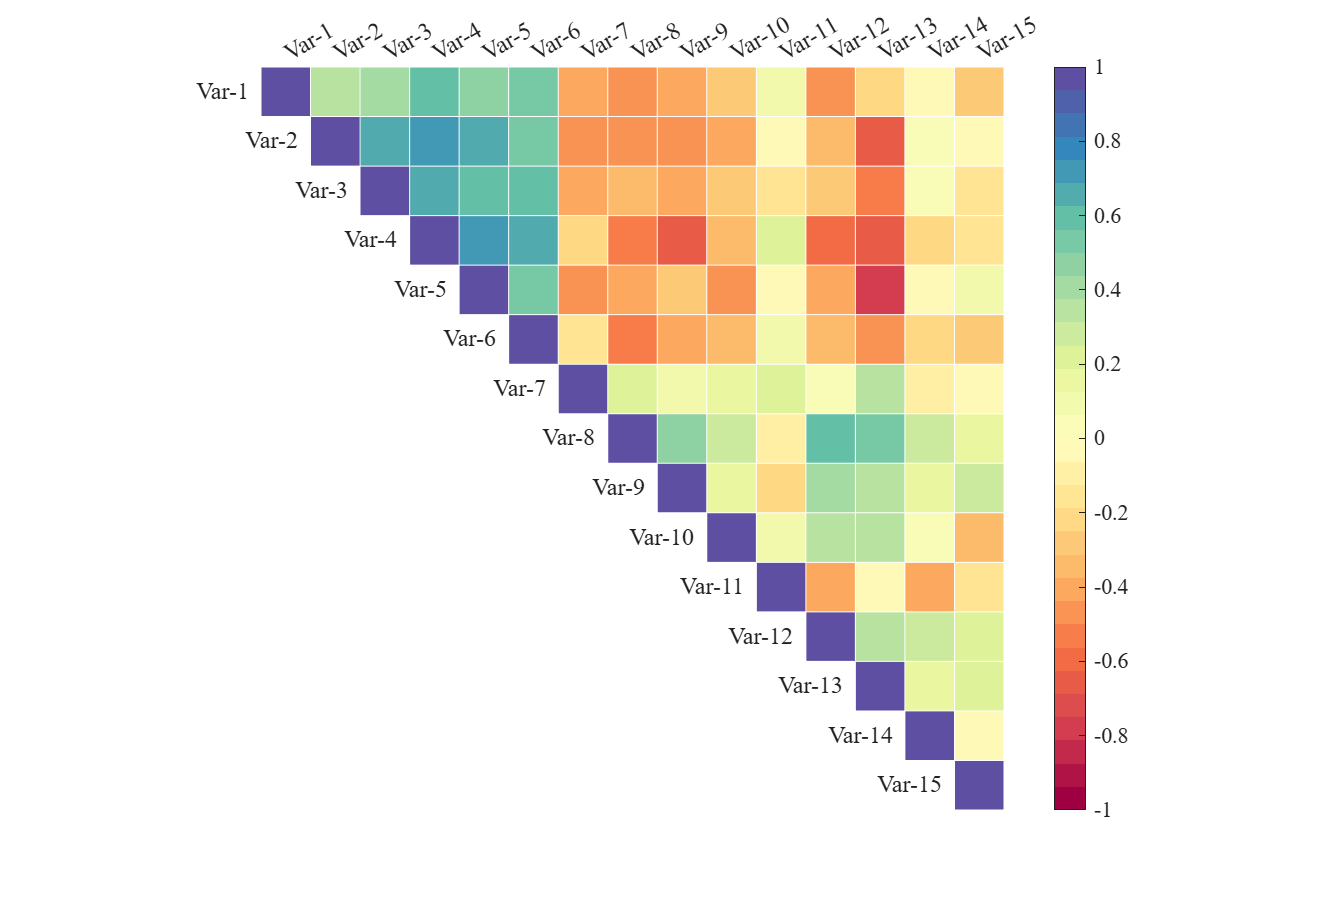

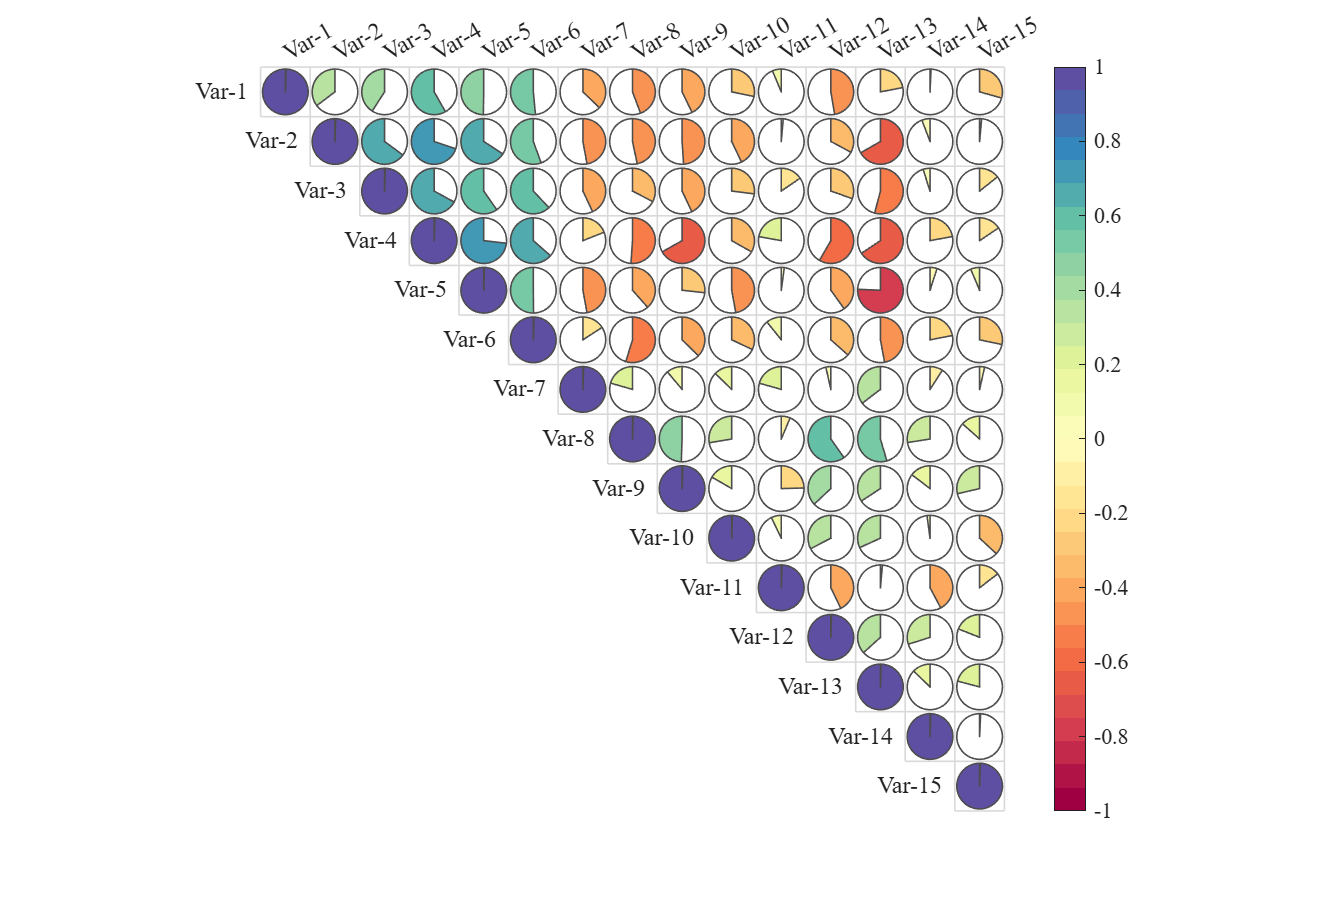

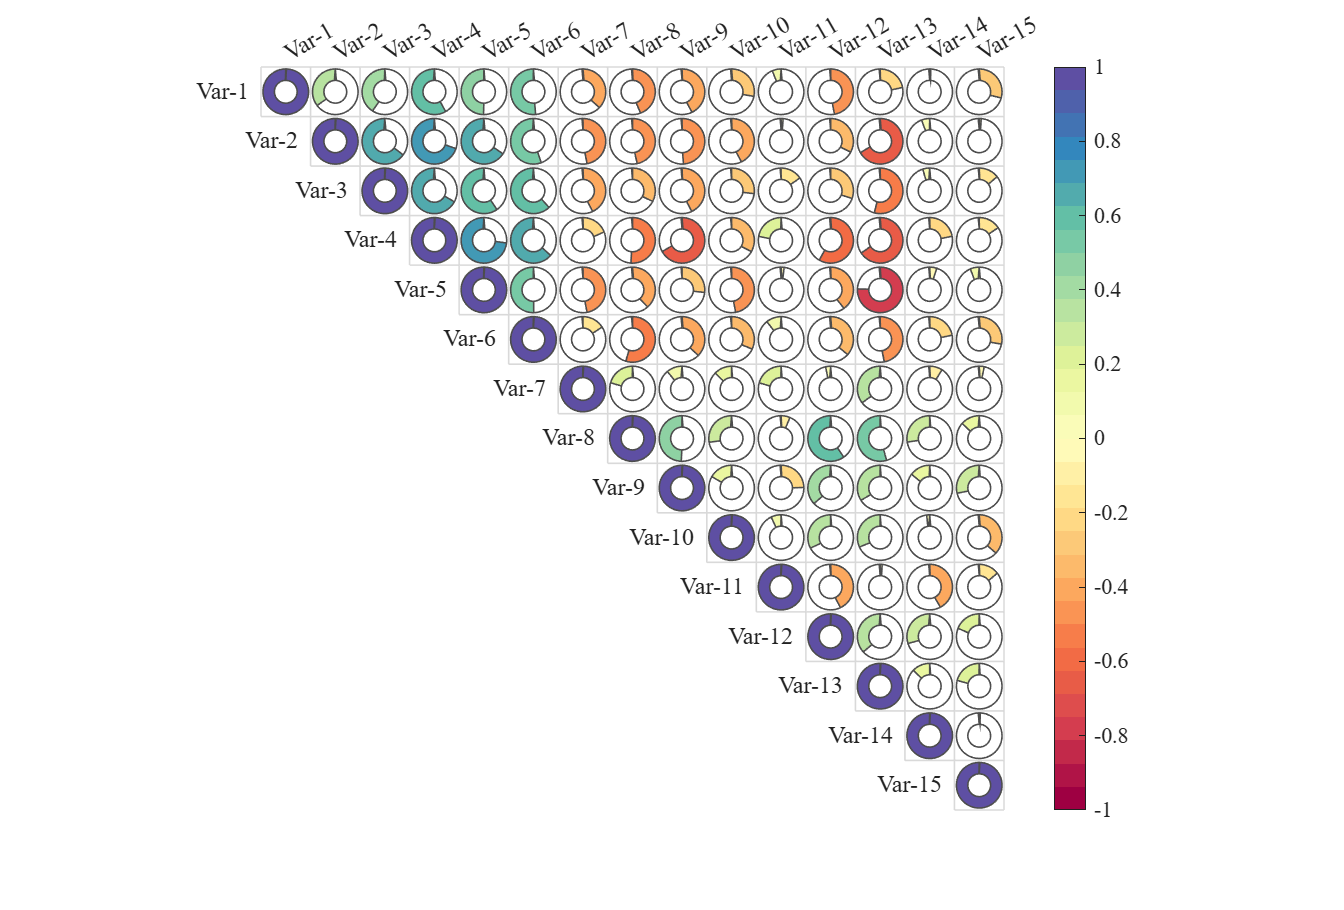

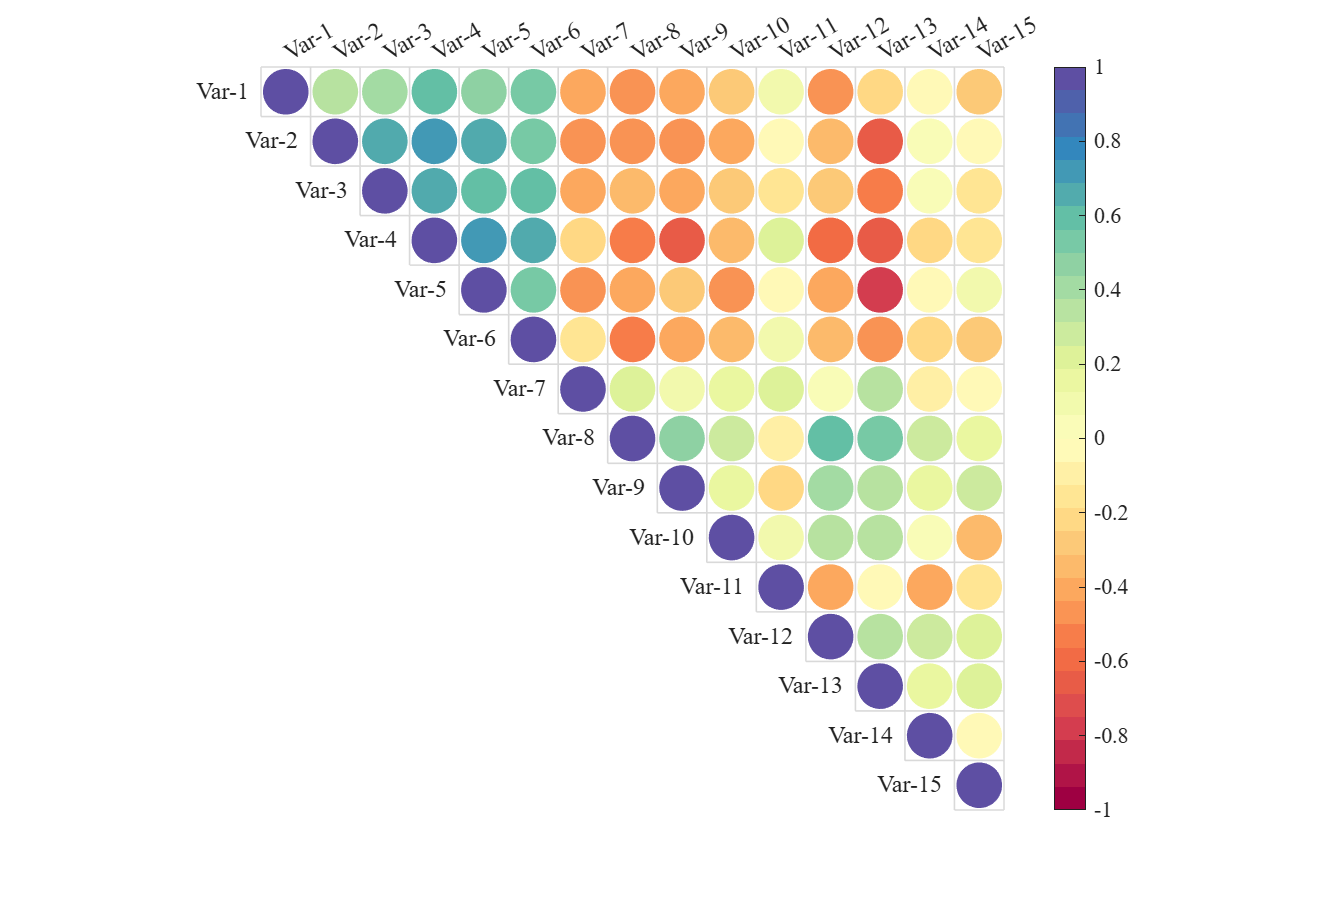

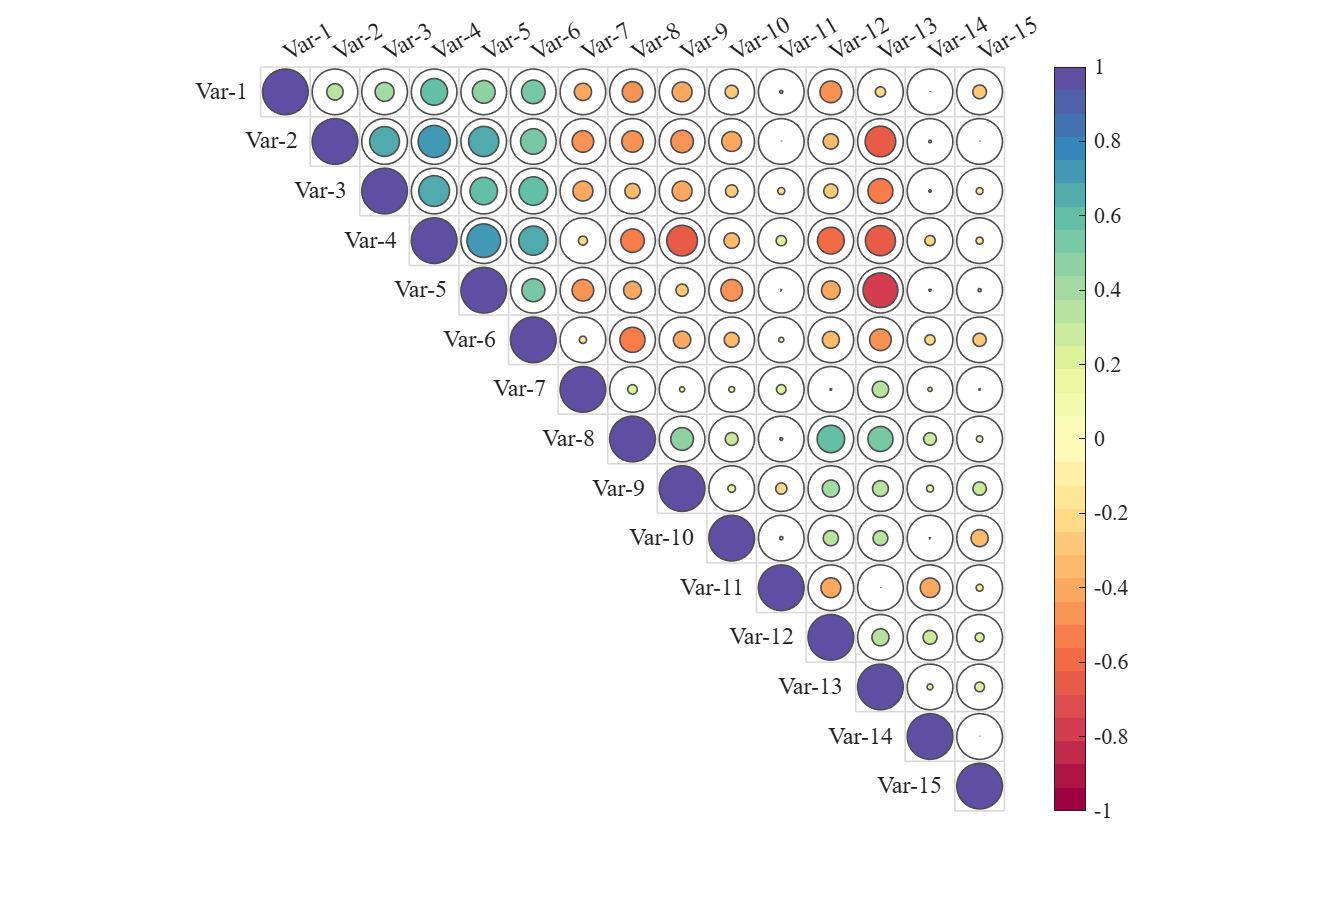

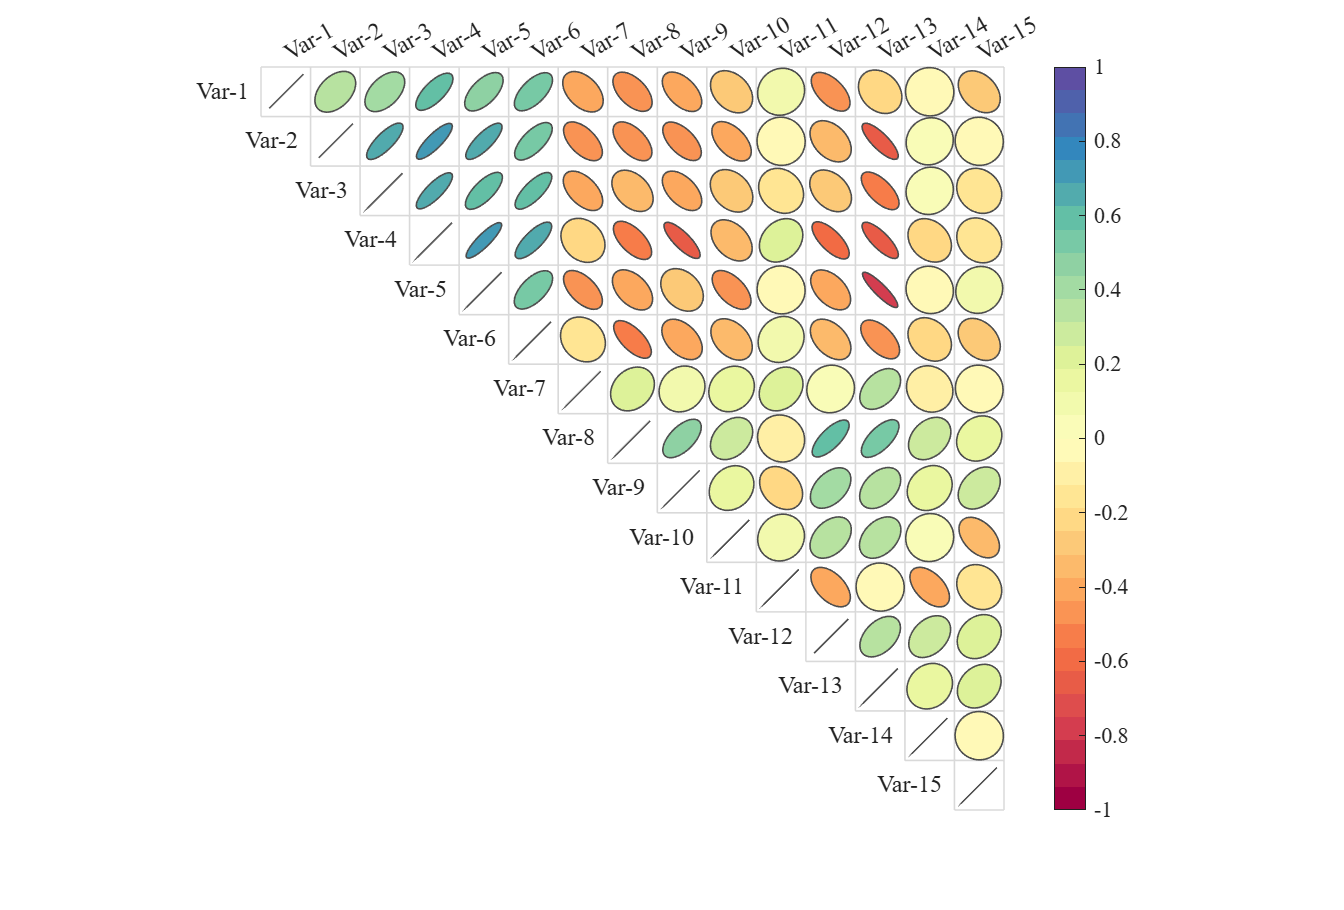

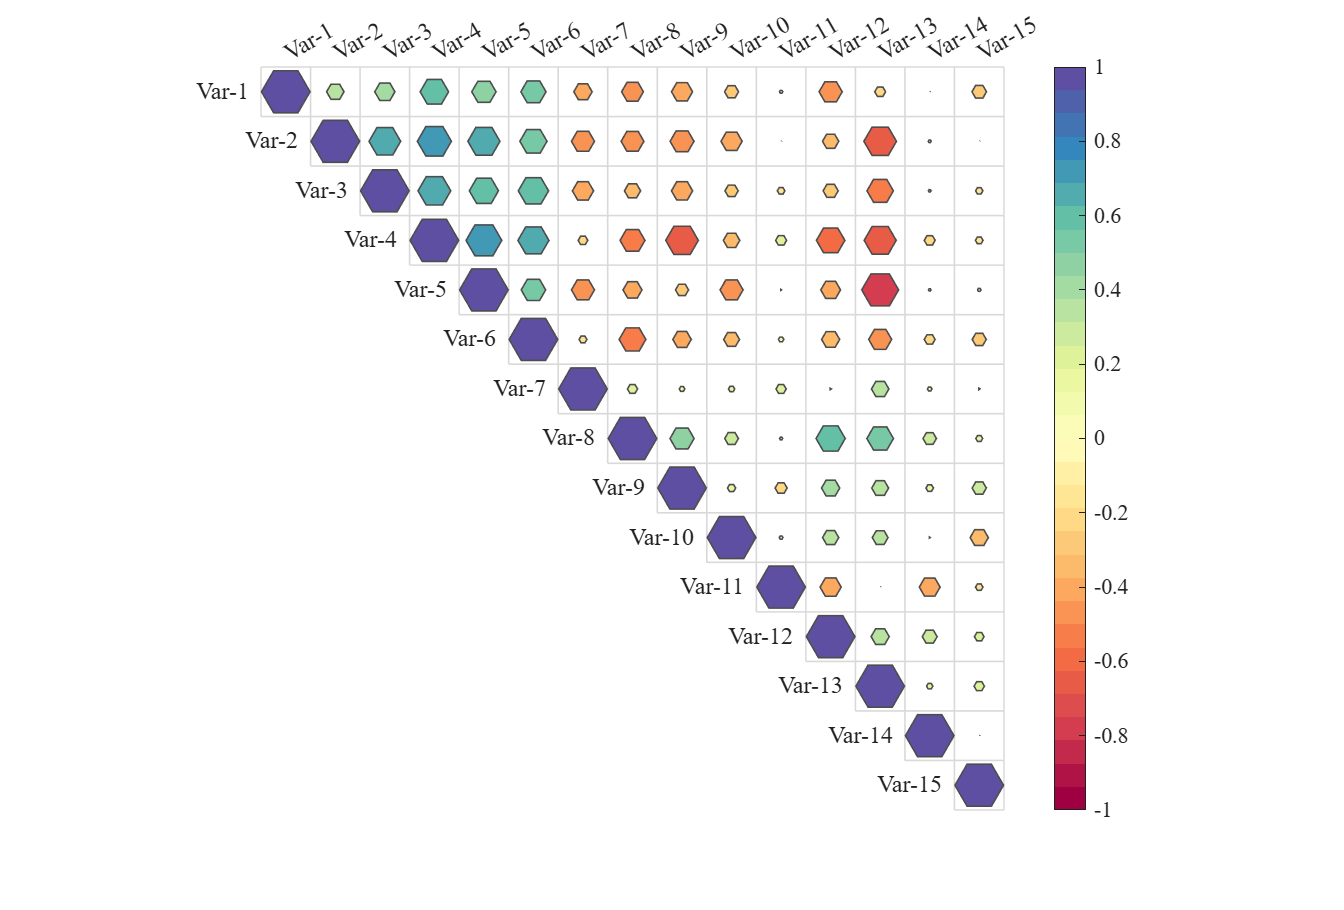

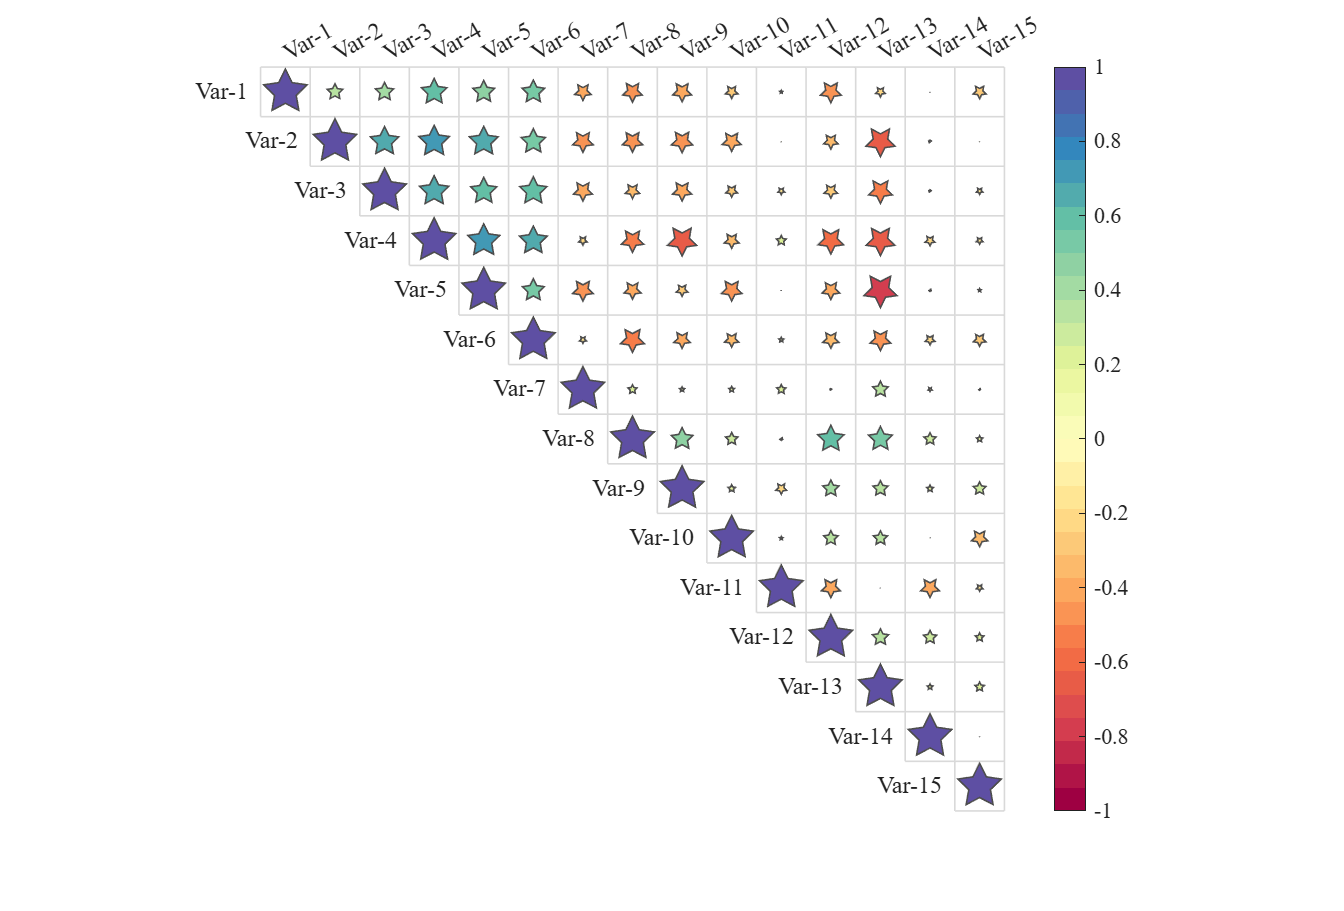

% Made up some data casually (随便捏造了点数据)
X=randn(20,15)+[(linspace(-1,2.5,20)').*ones(1,6),(linspace(.5,-.7,20)').*ones(1,5),(linspace(.9,-.2,20)').*ones(1,4)];
% Get the correlation matrix (求相关系数矩阵)
Data=corr(X);

Format={'sq','pie','donut','circ','bcirc','oval','hex','star','tril','triu','trilr','triul','asq','acirc'};
for i=1:length(Format)
    figure()
    SHM_s4=SHeatmap(Data,'Format',Format{i});
    SHM_s4=SHM_s4.draw();
    % set Type (设置格式)
    SHM_s4.setType('triu');
    % exportgraphics(gca,['gallery\Type_triu',Format{i},'.png'])

end

### 6.5 Set Label Font (设置标签字体)

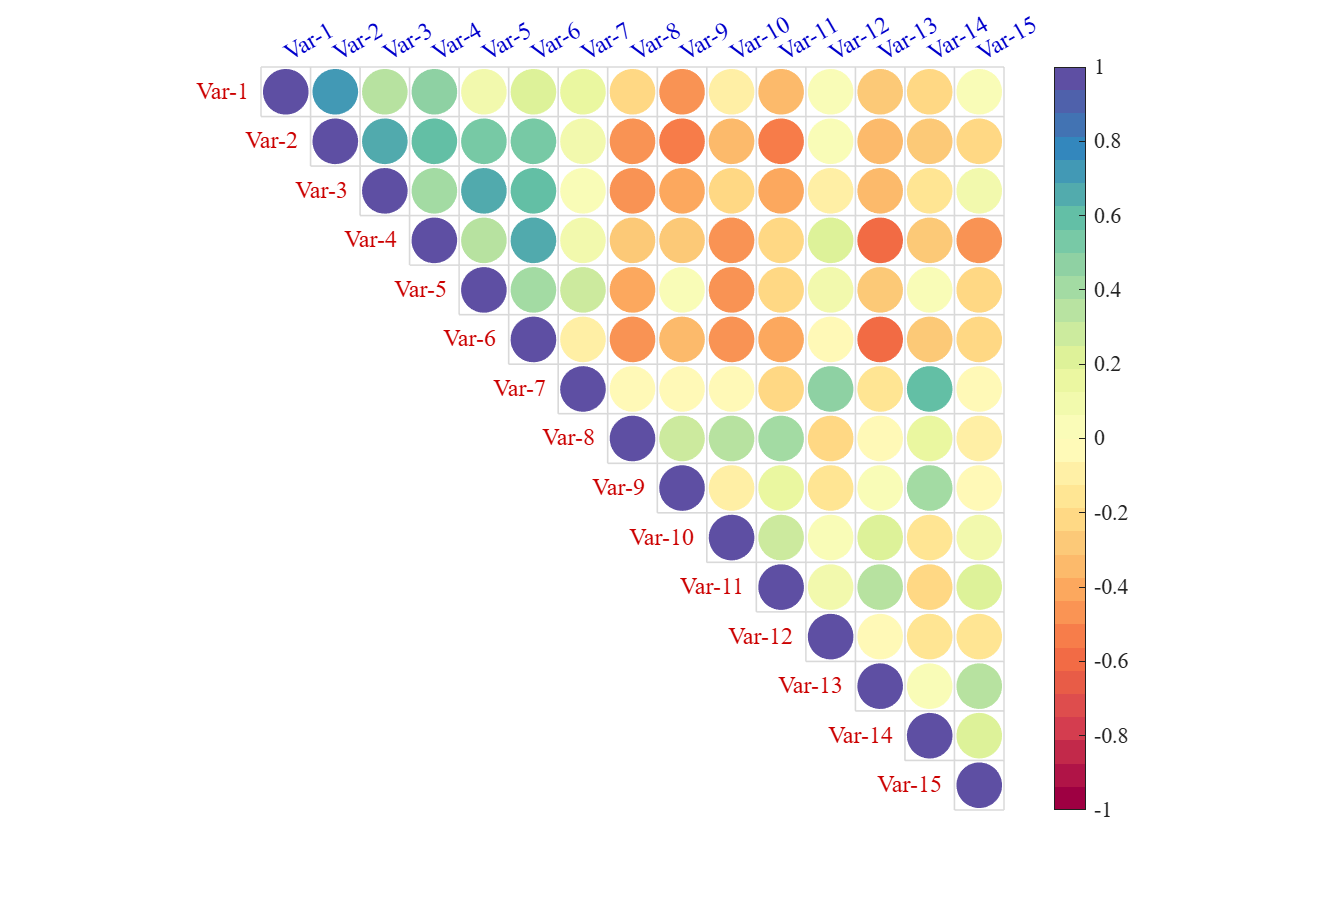

% Made up some data casually (随便捏造了点数据)
X=randn(20,15)+[(linspace(-1,2.5,20)').*ones(1,6),(linspace(.5,-.7,20)').*ones(1,5),(linspace(.9,-.2,20)').*ones(1,4)];
% Get the correlation matrix (求相关系数矩阵)
Data=corr(X);

figure()
SHM_s5=SHeatmap(Data,'Format','circ');
SHM_s5=SHM_s5.draw();
SHM_s5.setType('triu');
% Set Font Color (设置标签颜色)
SHM_s5.setRowLabel('Color',[.8,0,0])

SHM_s5.setColLabel('Color',[0,0,.8]) 

## 7 Merge two triangle heatmaps (合并两个三角热图)

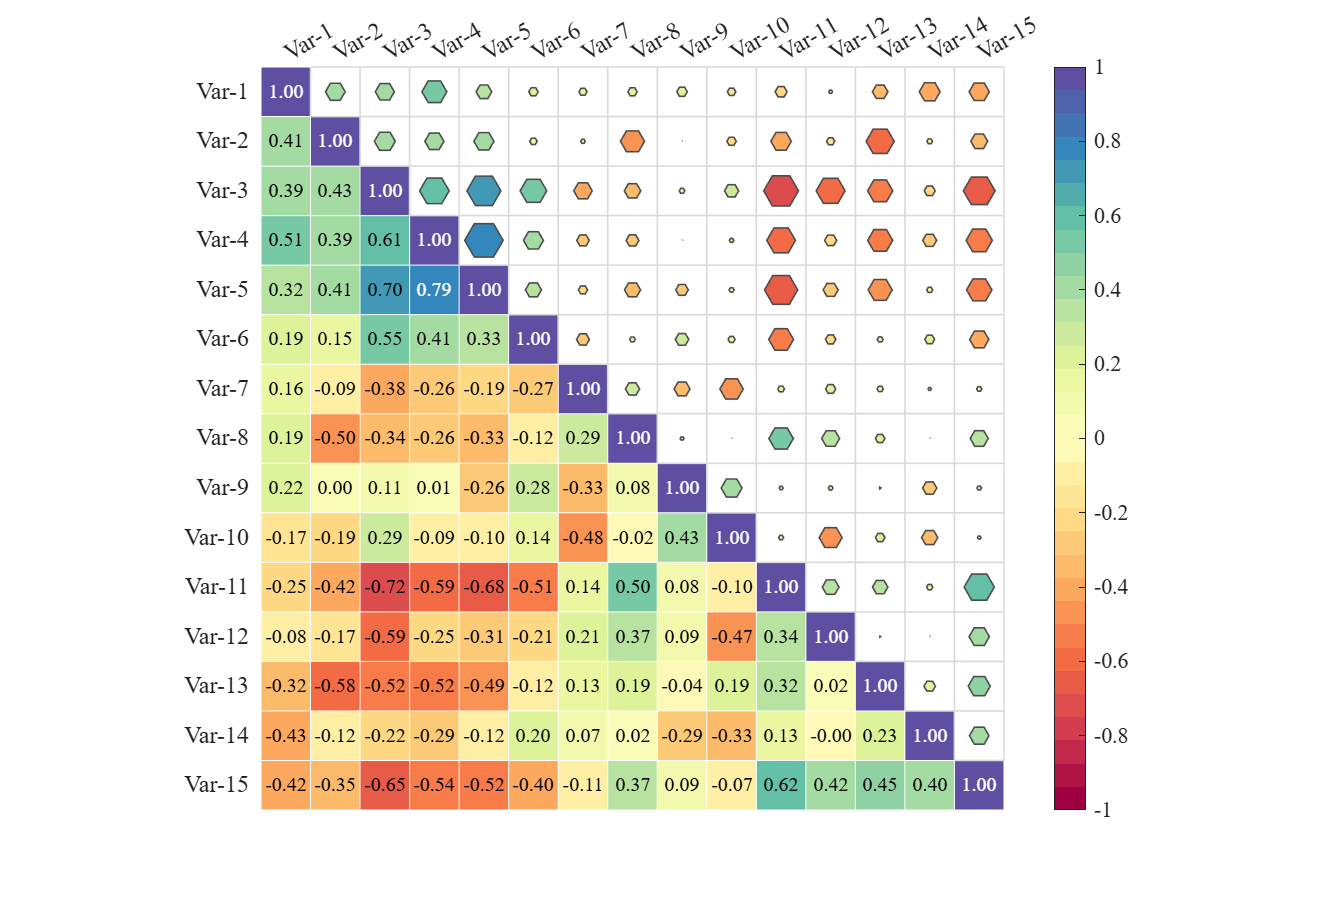

% Made up some data casually (随便捏造了点数据)
X=randn(20,15)+[(linspace(-1,2.5,20)').*ones(1,6),(linspace(.5,-.7,20)').*ones(1,5),(linspace(.9,-.2,20)').*ones(1,4)];
% Get the correlation matrix (求相关系数矩阵)
Data=corr(X);


figure()
SHM_m1=SHeatmap(Data,'Format','sq');
SHM_m1=SHM_m1.draw();
SHM_m1.setType('tril');
SHM_m1.setColLabel('Visible','off')

SHM_m2=SHeatmap(Data,'Format','hex');
SHM_m2=SHM_m2.draw();
SHM_m2.setType('triu0');
SHM_m2.setRowLabel('Visible','off')
SHM_m2.setColLabel('Visible','on') % Show the hidden Var-1 label (显示隐藏的Var-1标签)

% clim([-1.2,1.2])
% colormap(slanCM(141))


SHM_m1.setText();

### 7.2 Merge two triangle heat maps with two colormaps (合并两个三角热图且使用不同colormap)

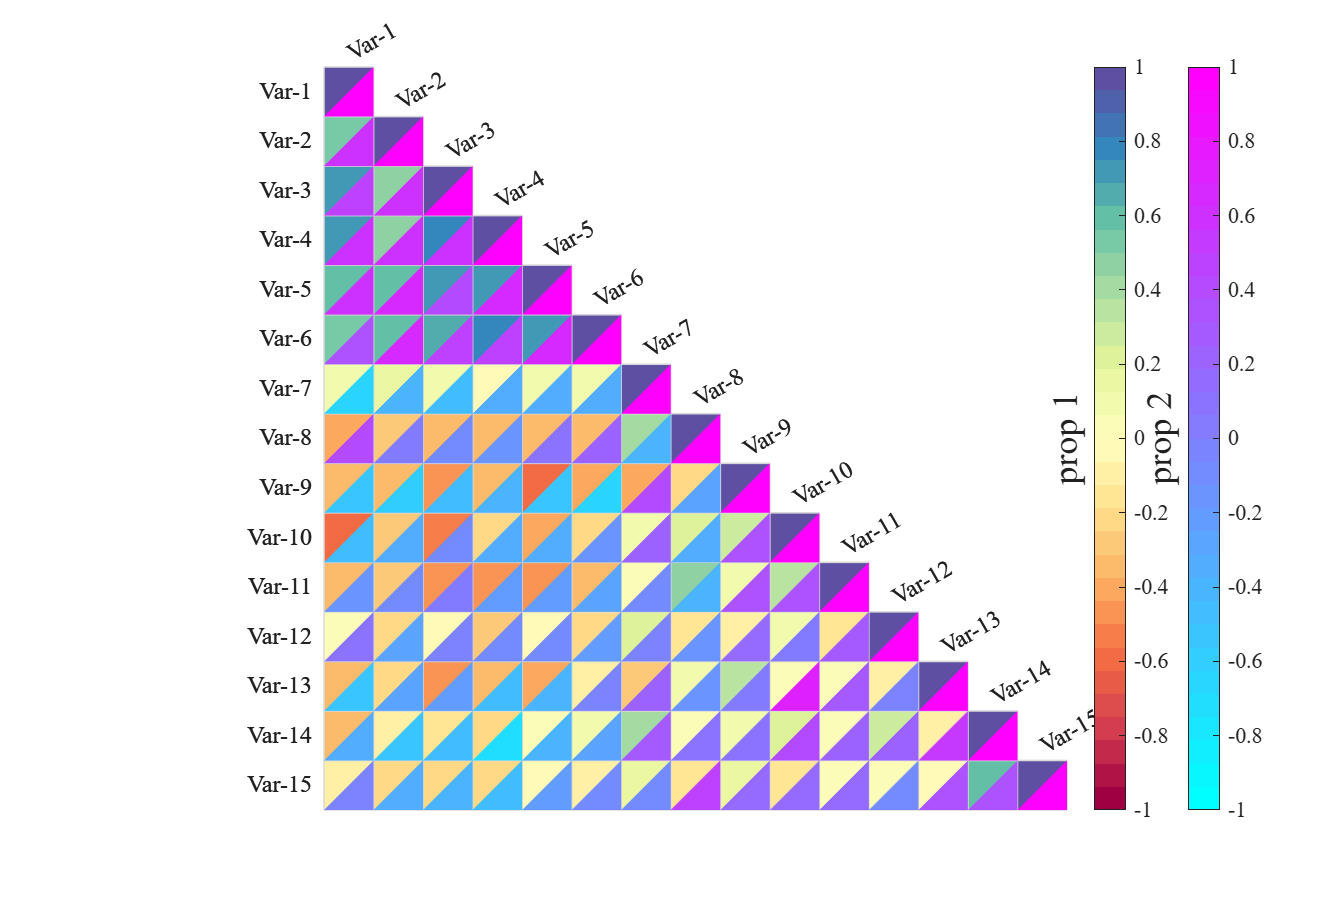

% Made up some data casually (随便捏造了点数据)
X1=randn(20,15)+[(linspace(-1,2.5,20)').*ones(1,6),(linspace(.5,-.7,20)').*ones(1,5),(linspace(.9,-.2,20)').*ones(1,4)];
X2=randn(20,15)+[(linspace(-1,2.5,20)').*ones(1,6),(linspace(.5,-.7,20)').*ones(1,5),(linspace(.9,-.2,20)').*ones(1,4)];
% Get the correlation matrix (求相关系数矩阵)
Data1=corr(X1);
Data2=corr(X2);


figure()
% Draw the first heatmap and freeze colors (绘制第一个热图并冻结配色)
SHM_m1=SHeatmap(Data1,'Format','triul');
SHM_m1=SHM_m1.draw();
SHM_m1=SHM_m1.setType('tril');
SHM_m1.freezeColors() 

SHM_m2=SHeatmap(Data2,'Format','trilr');
SHM_m2=SHM_m2.draw();
SHM_m2.setType('tril');
colormap(cool(32));
SHM_m2.Colorbar.Position(1) = SHM_m2.Colorbar.Position(1) + .1;


% Draw label for colorbars (为两个 colorbar 添加标签)
LB1 = SHM_m1.Colorbar.Label;
LB1.String = 'prop 1';
LB1.FontSize = 18;
LB1.Position = [-1.5, 0, 0];
LB2 = SHM_m2.Colorbar.Label;
LB2.String = 'prop 2';
LB2.FontSize = 18;

LB2.Position = [-1.5, 0, 0];

## 8 Heatmap with dendrogram (带树状图热图) 

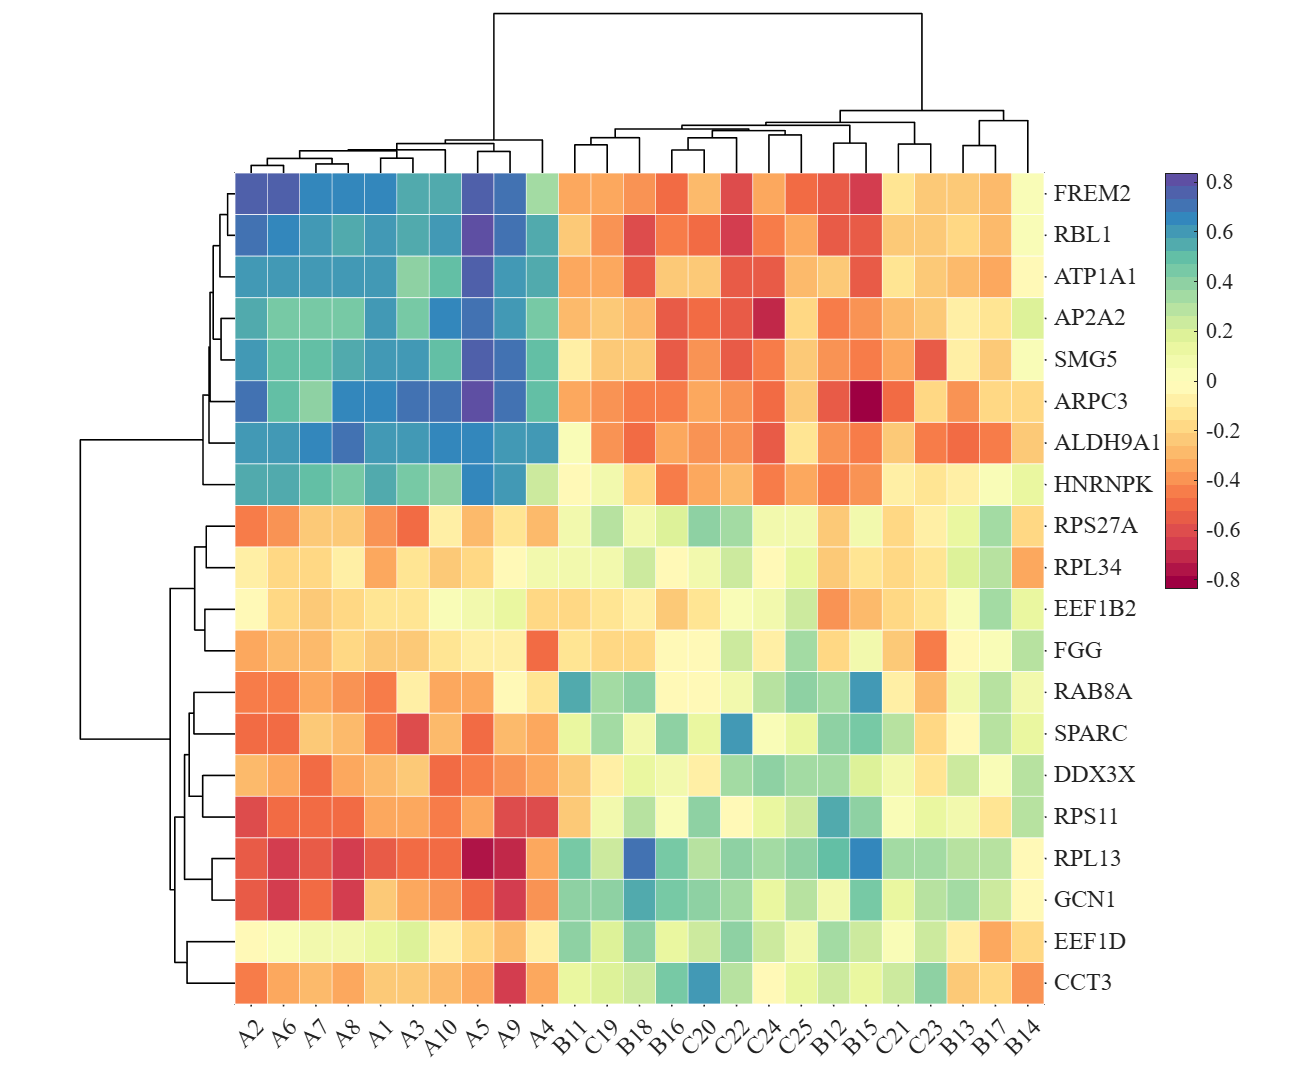

% Made up some data casually (随便捏造了点数据)
X1 = randn(20,20) + [(linspace(-1,2.5,20)').*ones(1,8),(linspace(.5,-.7,20)').*ones(1,5),(linspace(.9,-.2,20)').*ones(1,7)];
X2 = randn(20,25) + [(linspace(-1,2.5,20)').*ones(1,10),(linspace(.5,-.7,20)').*ones(1,8),(linspace(.9,-.2,20)').*ones(1,7)];
% Get the correlation matrix (求相关系数矩阵)
Data=corr(X1,X2);
% rowName and colName
rowName={'FREM2','ALDH9A1','RBL1','AP2A2','HNRNPK','ATP1A1','ARPC3','SMG5','RPS27A',...
          'RAB8A','SPARC','DDX3X','EEF1D','EEF1B2','RPS11','RPL13','RPL34','GCN1','FGG','CCT3'};
colName={'A1','A2','A3','A4','A5','A6','A7','A8','A9','A10','B11','B12','B13',...
         'B14','B15','B16','B17','B18','C19','C20','C21','C22','C23','C24','C25'};

% create figure (图窗创建)
fig=figure('Position',[100,100,870,720]);

% Adjust the position of the main coordinate area 
% and place the Y axis to the right (调整主坐标区域位置并将Y轴置于右侧)
axMain=axes('Parent',fig);
axMain.Position=[.18,.07,.62,.77];
P=axMain.Position;
axMain.YAxisLocation='right';

% Draw the left dendrogram (绘制左侧树状图)
axTreeL=axes('Parent',fig);
axTreeL.Position=[P(1)-P(3)/5,P(2),P(3)/5,P(4)];
orderL=SDendrogram(Data,'Orientation','left','Parent',axTreeL);

% Draw the top dendrogram (绘制顶部树状图)
axTreeT=axes('Parent',fig);
axTreeT.Position=[P(1),P(2)+P(4),P(3),P(4)/5];
orderT=SDendrogram(Data,'Orientation','top','Parent',axTreeT);

% Exchange data order (交换数据顺序)
Data=Data(orderL,:);
Data=Data(:,orderT);

% Draw Heatmap (绘制热图)
SHM_t1=SHeatmap(Data,'Format','sq','Parent',axMain);
SHM_t1.draw();
axMain.DataAspectRatioMode='auto';
axMain.XTickLabel=colName(orderT);
axMain.YTickLabel=rowName(orderL);
CB=colorbar(axMain);
CB.Position=[P(1)+P(3)*1.15,P(2)+P(4)/2,P(3)/25,P(4)/2];

## 9 Grouping heatmap (带分组热图)

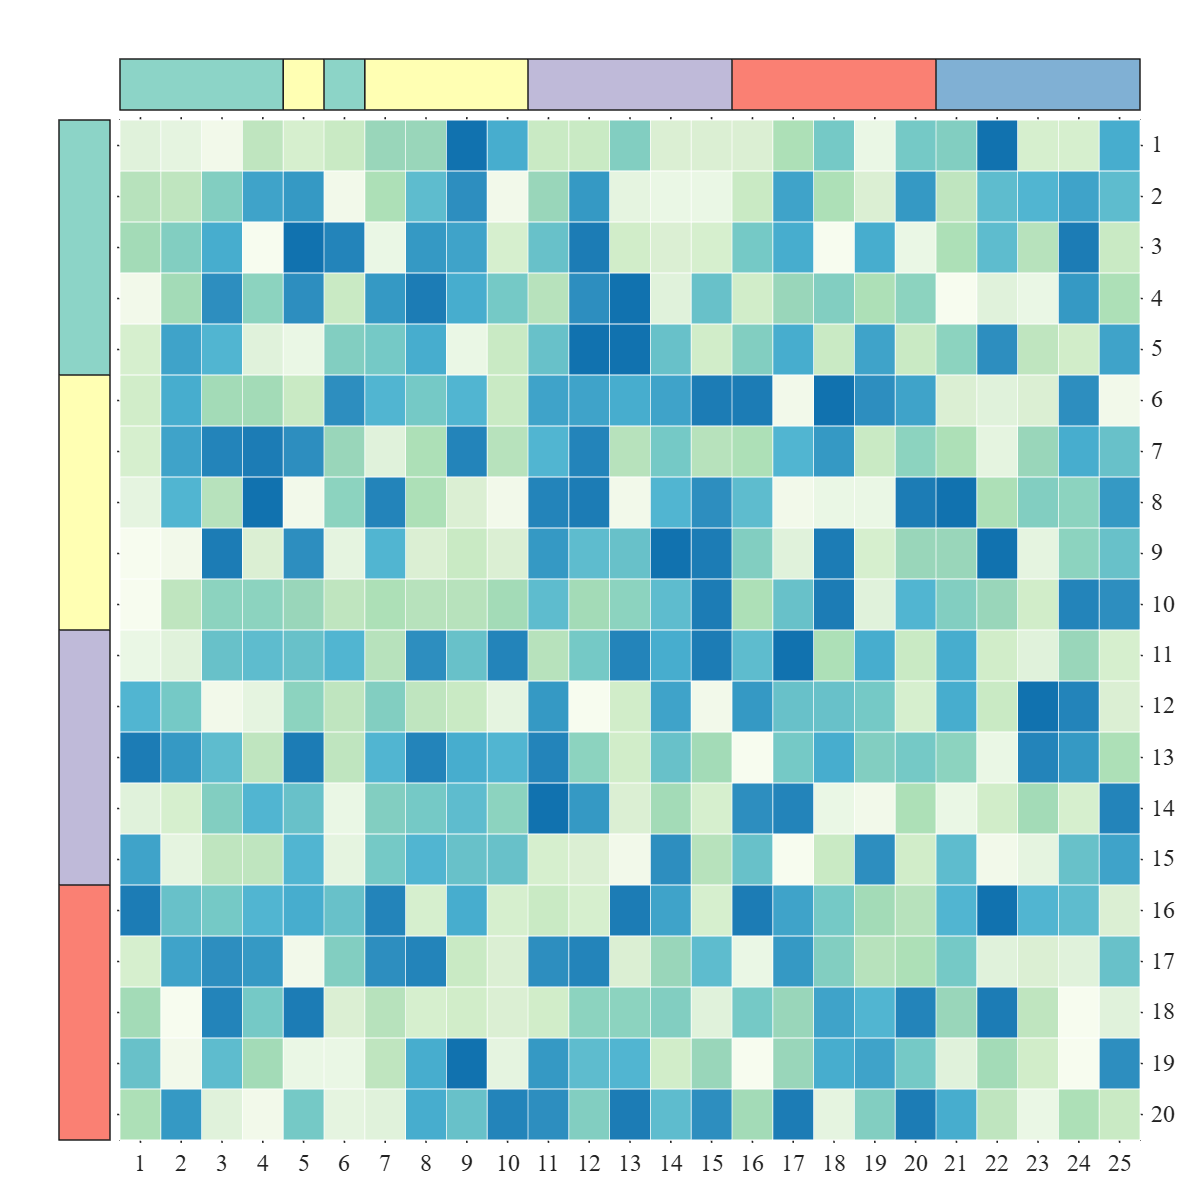

% Made up some data casually (随便捏造了点数据)
ClassCol=[1,1,1,1,2,1,2,2,2,2,3,3,3,3,3,4,4,4,4,4,5,5,5,5,5];
ClassRow=[1,1,1,1,1,2,2,2,2,2,3,3,3,3,3,4,4,4,4,4];
Data=rand(20,25);

% create figure (图窗创建)
fig=figure('Position',[100,100,800,800]);

% Adjust the position of the main coordinate area 
% and place the Y axis to the right (调整主坐标区域位置并将Y轴置于右侧)
axMain=axes('Parent',fig);
axMain.Position=[.1,.05,.85,.85];
P=axMain.Position;
axMain.YAxisLocation='right';

% Draw the left Block (绘制左侧分组方块)
axBlockL=axes('Parent',fig);
axBlockL.Position=[P(1)-P(3)/20-P(3)*.01,P(2),P(3)/20,P(4)];
SClusterBlock(ClassRow,'Orientation','left','Parent',axBlockL);

% Draw the top Block (绘制上侧分组方块)
axBlockT=axes('Parent',fig);
axBlockT.Position=[P(1),P(2)+P(4)*1.01,P(3),P(4)/20];
SClusterBlock(ClassCol,'Orientation','top','Parent',axBlockT);

% Draw Heatmap (绘制热图)
SHM_b1=SHeatmap(Data,'Format','sq','Parent',axMain);
SHM_b1=SHM_b1.draw();
axMain.DataAspectRatioMode='auto';
colorbar(axMain,'off');
clim(axMain,[-.2,1])

## 10 Multilayer grouping (多层分组)

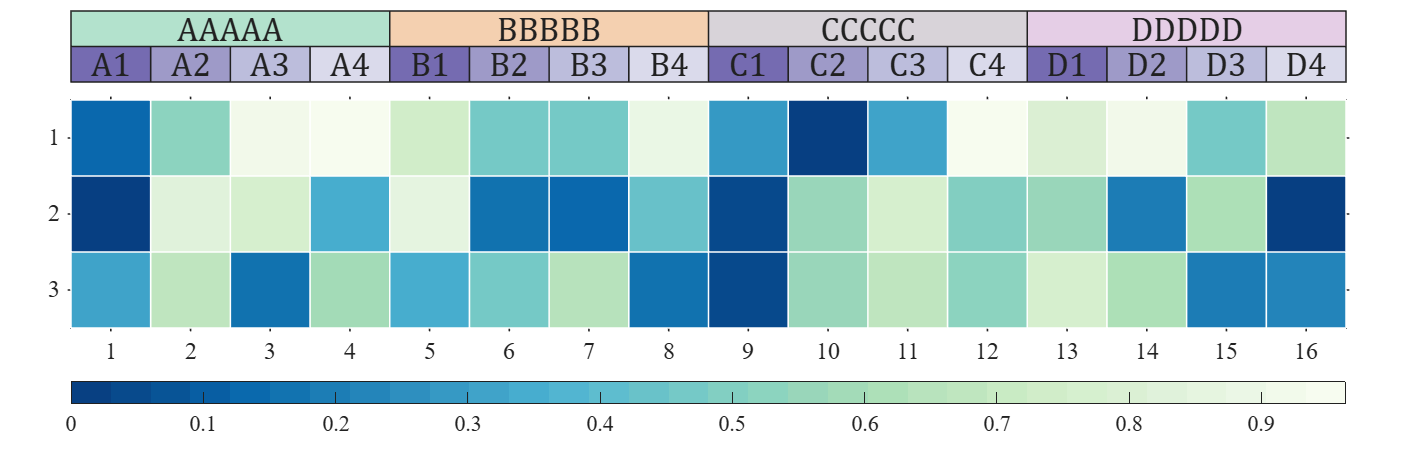

Data=rand(3,16);

Class1=[1,1,1,1,2,2,2,2,3,3,3,3,4,4,4,4];
Class2=[1,2,3,4,1,2,3,4,1,2,3,4,1,2,3,4];
ClassName1={'AAAAA','BBBBB','CCCCC','DDDDD'};
ClassName2={'A1','A2','A3','A4','B1','B2','B3','B4','C1','C2','C3','C4','D1','D2','D3','D4'};

% Set Color (设置颜色)
CList1=[0.7020    0.8863    0.8039
    0.9559    0.8142    0.6907
    0.8451    0.8275    0.8510
    0.8966    0.8083    0.9000];
CList2=[0.4588    0.4196    0.6941
    0.6196    0.6039    0.7843
    0.7373    0.7412    0.8627
    0.8549    0.8549    0.9216];

% create figure and axes (图窗及坐标区域创建)
fig=figure('Position',[100,100,1000,320]);
axMain=axes('Parent',fig);
axMain.Position=[.05,0,.9,.78];
P=axMain.Position;

% Draw Heatmap
SHM5=SHeatmap(Data,'Format','sq','Parent',axMain);
SHM5=SHM5.draw();
CB=colorbar;
CB.Location='southoutside';
axMain.DataAspectRatioMode='auto';

% Draw Block
axBlockT=axes('Parent',fig);
axBlockT.Position=[P(1),P(2)+P(4)*1.05,P(3),P(4)/5];
[X1,Y1]=SClusterBlock(Class1,'Orientation','top','Parent',axBlockT,'BasePos',1,'ColorList',CList1);
[X2,Y2]=SClusterBlock(Class2,'Orientation','top','Parent',axBlockT,'ColorList',CList2);

% text
for i=1:length(X1)
    text(axBlockT,X1(i),Y1(i),ClassName1{i},'FontSize',17,'HorizontalAlignment','center','FontName','Cambria')
end
for i=1:length(X2)
    text(axBlockT,X2(i),Y2(i),ClassName2{i},'FontSize',17,'HorizontalAlignment','center','FontName','Cambria')
end

## 11 Tree and Group (树状图及分组)

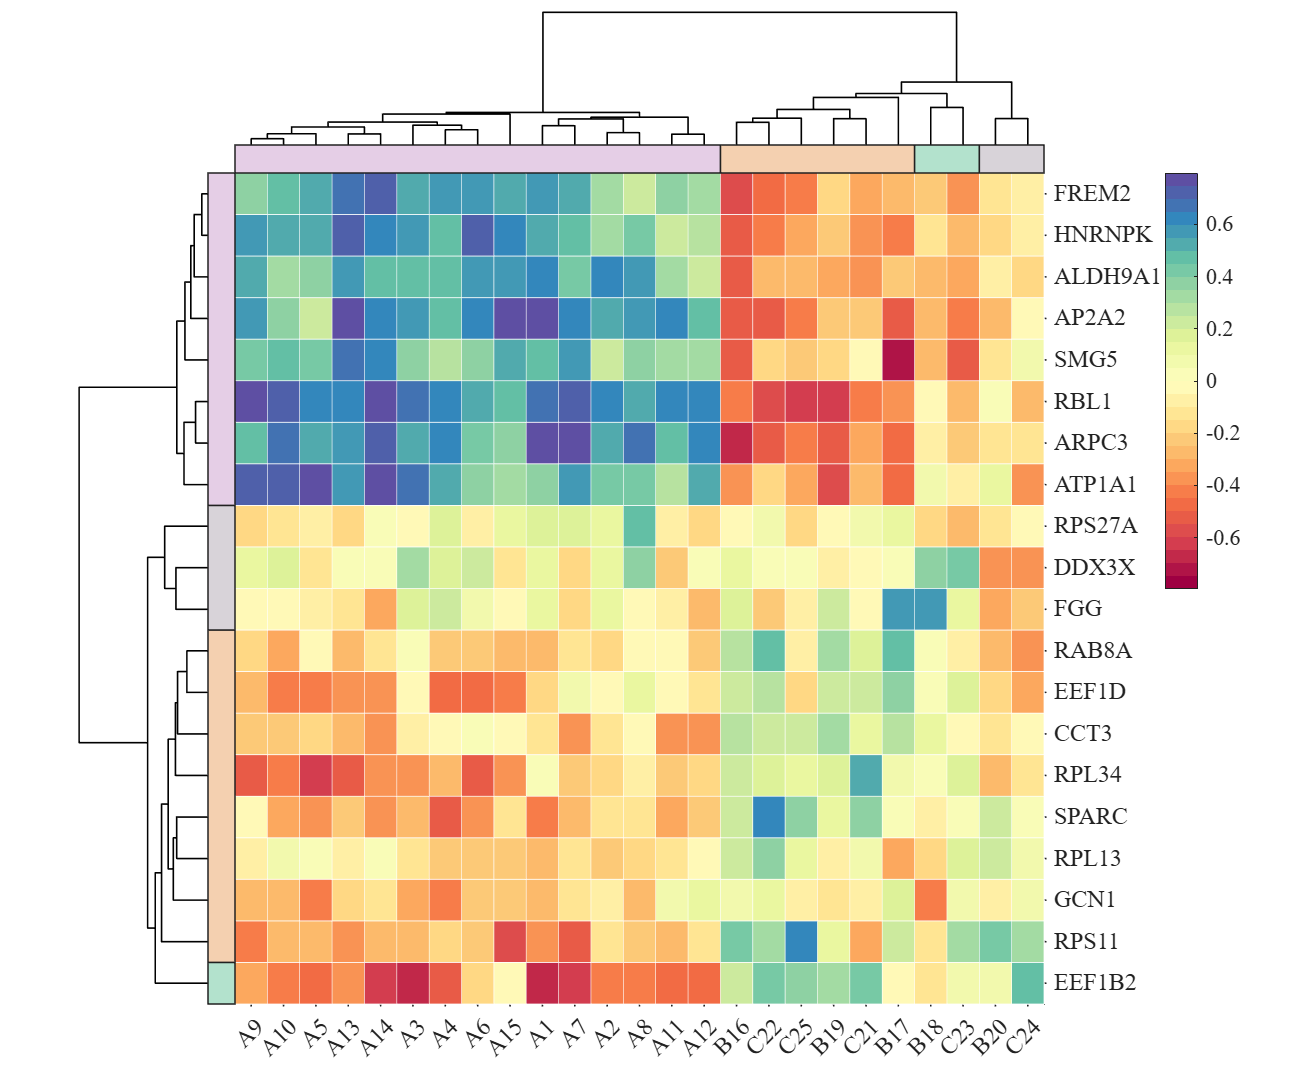

% Made up some data casually (随便捏造了点数据)
X1=randn(20,20)+[(linspace(-1,2.5,20)').*ones(1,8),(linspace(.5,-.7,20)').*ones(1,5),(linspace(.9,-.2,20)').*ones(1,7)];
X2=randn(20,25)+[(linspace(-1,2.5,20)').*ones(1,15),(linspace(.5,-.7,20)').*ones(1,5),(linspace(.9,-.2,20)').*ones(1,5)];
% Get the correlation matrix (求相关系数矩阵)
Data=corr(X1,X2);
% rowName and colName
rowName={'FREM2','ALDH9A1','RBL1','AP2A2','HNRNPK','ATP1A1','ARPC3','SMG5','RPS27A',...
          'RAB8A','SPARC','DDX3X','EEF1D','EEF1B2','RPS11','RPL13','RPL34','GCN1','FGG','CCT3'};
colName={'A1','A2','A3','A4','A5','A6','A7','A8','A9','A10','A11','A12','A13',...
         'A14','A15','B16','B17','B18','B19','B20','C21','C22','C23','C24','C25'};
% Set Color
CList=[0.7020    0.8863    0.8039
    0.9559    0.8142    0.6907
    0.8451    0.8275    0.8510
    0.8966    0.8083    0.9000];

% create figure (图窗创建)
fig=figure('Position',[100,100,870,720]);

% Adjust the position of the main coordinate area 
% and place the Y axis to the right (调整主坐标区域位置并将Y轴置于右侧)
axMain=axes('Parent',fig);
axMain.Position=[.18,.07,.62,.77];
P=axMain.Position;
axMain.YAxisLocation='right';

% Draw the left dendrogram (绘制左侧树状图)
axTreeL=axes('Parent',fig);
axTreeL.Position=[P(1)-P(3)/5,P(2),P(3)/5*(5/6),P(4)];
orderL=SDendrogram(Data,'Orientation','left','Parent',axTreeL,'Method','average');

% Draw the top dendrogram (绘制顶部树状图)
axTreeT=axes('Parent',fig);
axTreeT.Position=[P(1),P(2)+P(4)+P(4)/5*(1/6),P(3),P(4)/5*(5/6)];
orderT=SDendrogram(Data,'Orientation','top','Parent',axTreeT,'Method','average');

% Draw the left Block (绘制左侧分组方块)
axBlockL=axes('Parent',fig);
axBlockL.Position=[P(1)-P(3)/5+P(3)/5*(5/6),P(2),P(3)/5*(1/6),P(4)];
ZL=linkage(Data,'average');
CL=cluster(ZL,'Maxclust',4);
CL=CL(orderL);
SClusterBlock(CL,'Orientation','left','Parent',axBlockL,'ColorList',CList);

% Draw the top Block (绘制顶部分组方块)
axBlockT=axes('Parent',fig);
axBlockT.Position=[P(1),P(2)+P(4),P(3),P(4)/5*(1/6)];
ZT=linkage(Data.','average');
CT=cluster(ZT,'Maxclust',4);
CT=CT(orderT);
SClusterBlock(CT,'Orientation','top','Parent',axBlockT,'ColorList',CList);

% Exchange data order (交换数据顺序)
Data=Data(orderL,:);
Data=Data(:,orderT);

% Draw Heatmap (绘制热图)
SHM_t1=SHeatmap(Data,'Format','sq','Parent',axMain);
SHM_t1=SHM_t1.draw();
axMain.DataAspectRatioMode='auto';
axMain.XTickLabel=colName(orderT);
axMain.YTickLabel=rowName(orderL);
CB=colorbar(axMain);
CB.Position=[P(1)+P(3)*1.15,P(2)+P(4)/2,P(3)/25,P(4)/2];

## 12 Text Format (数值文本格式)

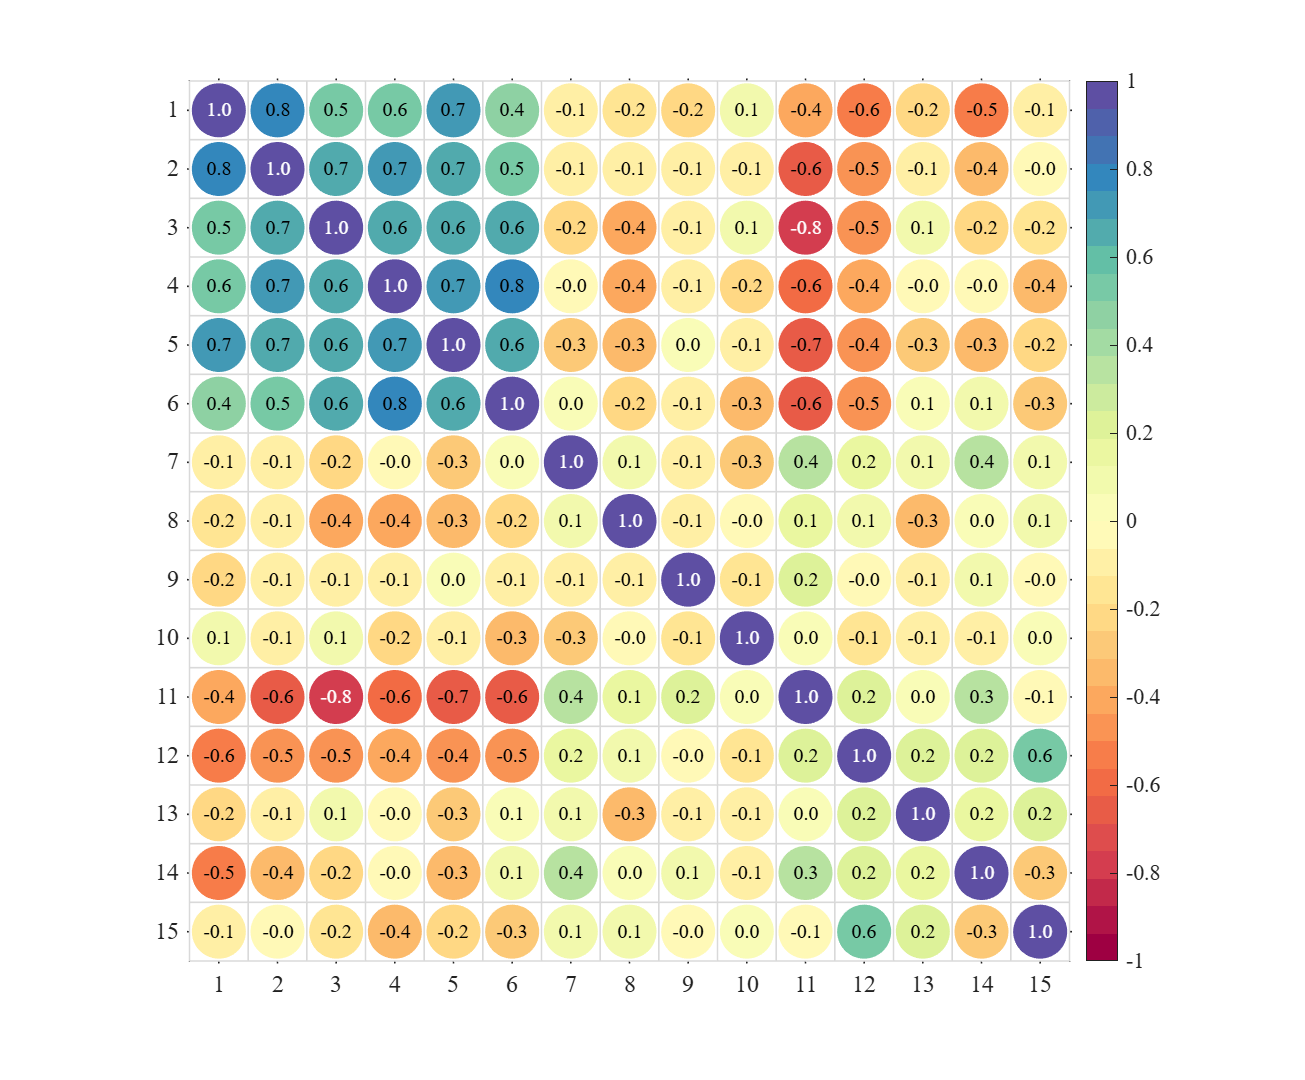

% Made up some data casually (随便捏造了点数据)
X=randn(20,15)+[(linspace(-1,2.5,20)').*ones(1,6),(linspace(.5,-.7,20)').*ones(1,5),(linspace(.9,-.2,20)').*ones(1,4)];
% Get the correlation matrix (求相关系数矩阵)
Data=corr(X);

% create figure (图窗创建)
figure('Position',[100,100,870,720]);

% Draw heat map with texts (绘制有文本热图)
SHM12=SHeatmap(Data,'Format','circ');
SHM12=SHM12.draw();
SHM12.setText();

% Set text format (调整数值文本格式)
SHM12.setTextFormat(@(x)sprintf('%0.1f',x))

% exportgraphics(gca,['gallery\Text_Format_','0.1f','.png'])

% SHM12.setTextFormat(@(x)sprintf('%0.1fS',x))
% exportgraphics(gca,['gallery\Text_Format_','0.1fS','.png'])
% SHM12.setTextFormat(@(x)sprintf('%0.1e',x))
% exportgraphics(gca,['gallery\Text_Format_','0.1e','.png'])


### 12.2 Displaying significance (显示显著性)

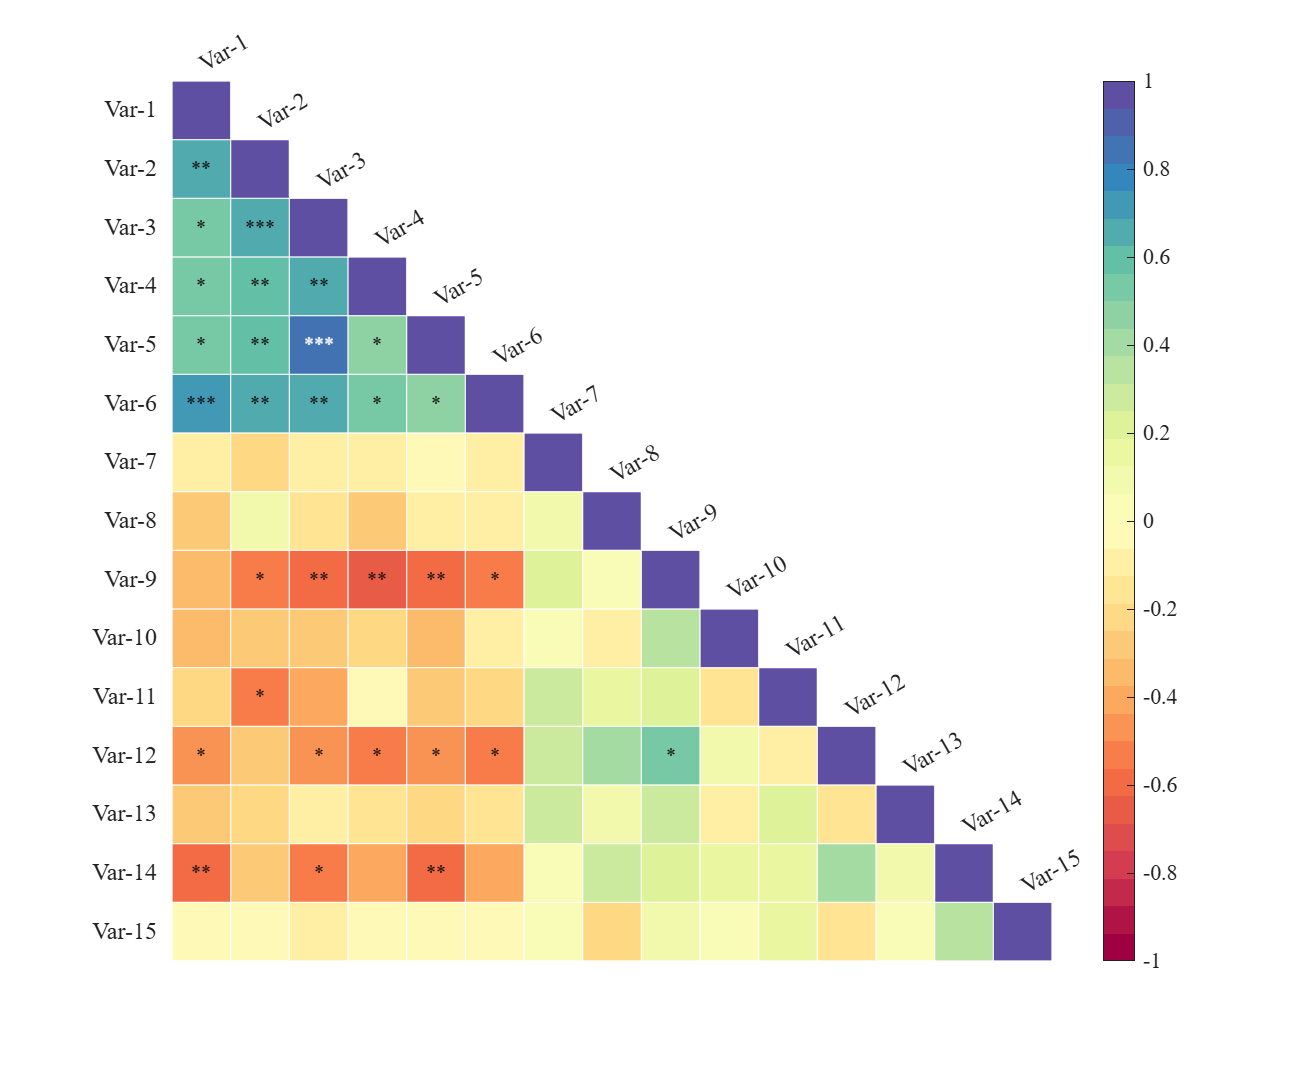

% Made up some data casually (随便捏造了点数据)
X=randn(20,15)+[(linspace(-1,2.5,20)').*ones(1,6),(linspace(.5,-.7,20)').*ones(1,5),(linspace(.9,-.2,20)').*ones(1,4)];
% Get the correlation matrix (求相关系数矩阵)
[Data, pval]=corr(X);

% create figure (图窗创建)
fig=figure('Position',[100,100,870,720]);

% Draw heat map with texts (绘制有文本热图)
SHM12=SHeatmap(Data,'Format','sq');
SHM12=SHM12.draw();
SHM12.setText();
SHM12.setType('tril');

% Displaying significance (显示显著性)
SHM12.showStars(pval, 'Levels', [0.05, 0.01, 0.001])

SHM12.showStars(pval, 'Levels', [0.05, 0.01, 0.001], 'CorrLabel','off')

## 13 Tiledlayout (Tiledlayout 布局)

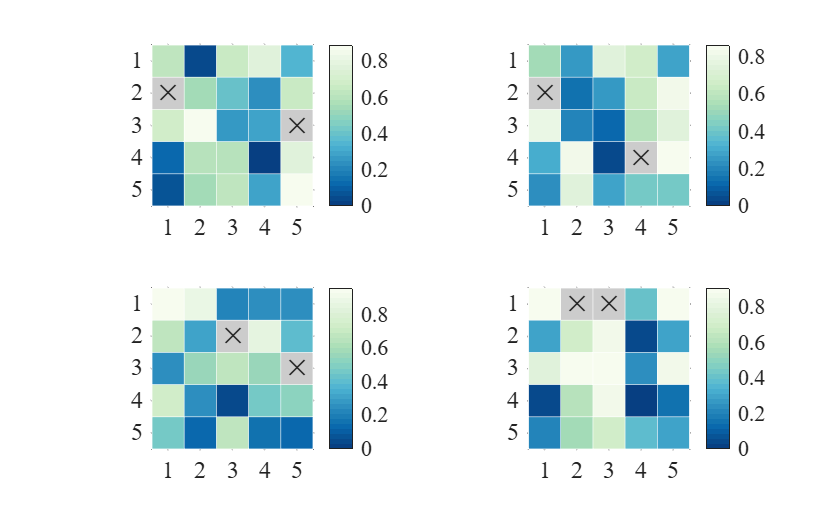

figure()
tiledlayout(2,2)

nexttile
Data=rand(5,5);
Data(randi([1,25], [2,1])) = nan;
SHM1=SHeatmap(Data,'Format','sq');
SHM1=SHM1.draw();

nexttile
Data=rand(5,5);
Data(randi([1,25], [2,1])) = nan;
SHM2=SHeatmap(Data,'Format','sq');
SHM2=SHM2.draw();

nexttile
Data=rand(5,5);
Data(randi([1,25], [2,1])) = nan;
SHM3=SHeatmap(Data,'Format','sq');
SHM3=SHM3.draw();

nexttile
Data=rand(5,5);
Data(randi([1,25], [2,1])) = nan;
SHM4=SHeatmap(Data,'Format','sq');
SHM4=SHM4.draw();

## 14 Heatmap with Mantel test links (带 Mantel 链接的热图)

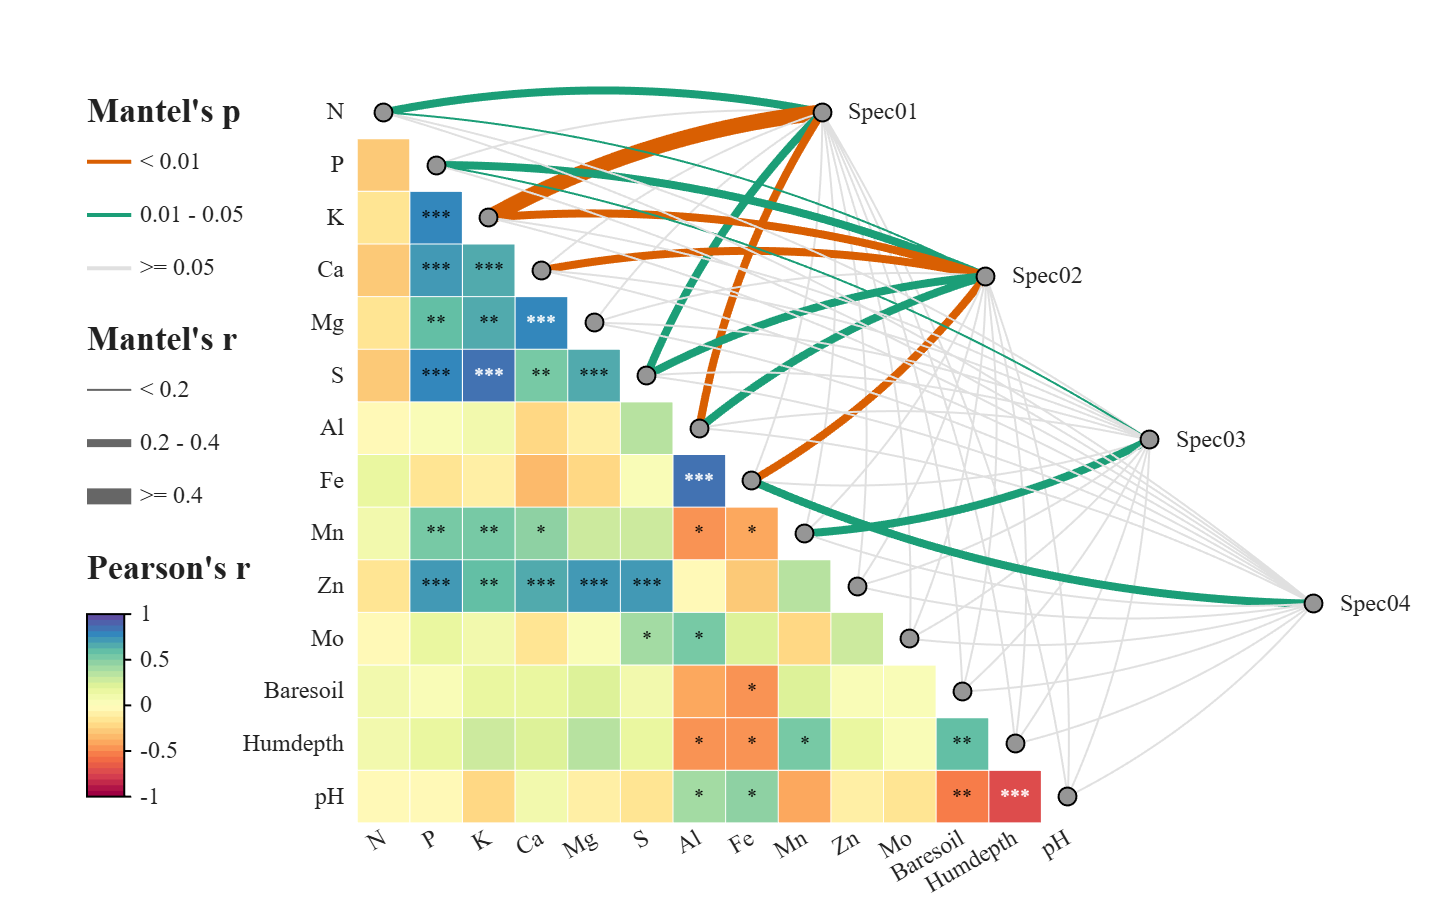

rng(7)
%% Load data (加载数据)
load('lichenData.mat')                  % Load pre-saved data package (加载预存的数据包)
Data1 = varechem.Variables;             % Environmental matrix (环境因子矩阵)
Data2 = varespec.Variables;             % Species composition matrix (物种组成矩阵)
labels = varechem.Properties.VariableNames; % Environmental variable names (环境变量名称)

% Define species groups: 44 columns into 4 groups (将44个物种列分为4组)
groupName = {'Spec01', 'Spec02', 'Spec03', 'Spec04'};
group = zeros(1, size(Data2, 2));
group(1:7) = 1;    % Group 1: columns 1-7 (第1组：列1-7)
group(8:18) = 2;   % Group 2: columns 8-18 (第2组：列8-18)
group(19:37) = 3;  % Group 3: columns 19-37 (第3组：列19-37)
group(38:44) = 4;  % Group 4: columns 38-44 (第4组：列38-44)


%% Figure and axes
fig = figure('Units','normalized', 'Position',[.05,.15,.72,.72]); 
ax = axes('Parent',fig, 'Position',[.06,.05,.88,.9]); 

%% Draw heatmap
[rho, pval] = corr(Data1);
objHM = SHeatmap(ax, rho, 'Format','sq');
objHM.draw();

% Display significance stars: p < 0.05 *, p < 0.01 **, p < 0.001 *** 
objHM.setText()
objHM.showStars(pval, 'Levels', [0.05, 0.01, 0.001], 'CorrLabel','off')

objHM.setVarName(labels)             % Set row/column labels (设置行列标签)
objHM.setType('tril0');              % Show only lower triangle without diagonal (仅显示下三角矩阵，不含对角线)
% Adjust label positions (调整标签位置)
objHM.setRowLabelLocation('left')    
objHM.setColLabelLocation('bottom')
% Show all labels, including those that were previously hidden. (显示所有标签，包括被隐藏的标签)
objHM.setRowLabel('Visible','on')
objHM.setColLabel('Visible','on')
delete(objHM.Colorbar)

%% Draw mantel links
% Create Mantel link object with env data, species data and groups (创建Mantel链接对象，传入环境数据、物种数据及分组信息)
objML = SMantelLink(ax, Data1, Data2, 'Group',group);
objML.GroupName = groupName;          % Set group names (设置组名)
objML.LegendLocation = 'west';        % Place legend on the left (图例置于左侧)
objML.Layout = 'triu';                % Links placed in upper triangle (链接采用上三角布局)
objML.draw()                          % Render the links (渲染链接图)

### 14.2 Heatmap with Mantel test links - tril layout (链接在左下方)

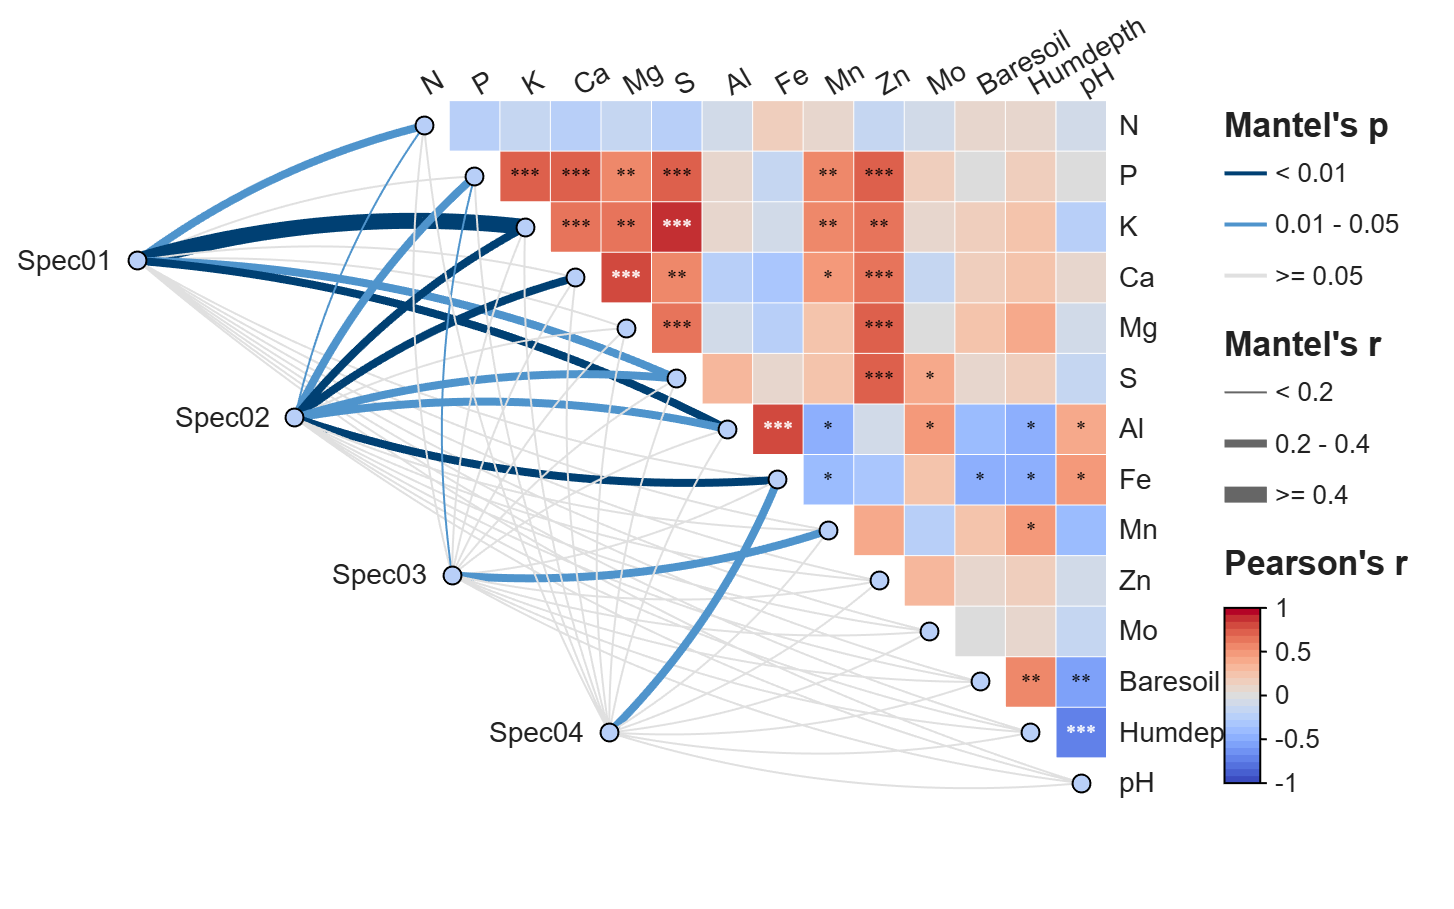

rng(7)
%% Load data
load('lichenData.mat')
Data1 = varechem.Variables;
Data2 = varespec.Variables;
labels = varechem.Properties.VariableNames;

groupName = {'Spec01', 'Spec02', 'Spec03', 'Spec04'};
group = zeros(1, size(Data2, 2));
group(1:7) = 1; 
group(8:18) = 2;
group(19:37) = 3;
group(38:44) = 4;

%% Figure and axes
fig = figure('Units','normalized', 'Position',[.05,.15,.72,.72]); 
ax = axes('Parent',fig, 'Position',[.06,.05,.88,.9]); 

%% Draw heatmap
[rho, pval] = corr(Data1);
objHM = SHeatmap(ax, rho, 'Format','sq');
objHM.draw();

objHM.setText()
objHM.showStars(pval, 'Levels', [0.05, 0.01, 0.001], 'CorrLabel','off')
objHM.setVarName(labels)
objHM.setType('triu0');
objHM.setRowLabelLocation('right')
objHM.setColLabelLocation('top')
objHM.setRowLabel('Visible','on')
objHM.setColLabel('Visible','on')
delete(objHM.Colorbar)

% Apply a custom colormap with 25 colors (应用自定义 25 色 colormap)
colormap(slanCM(102, 25))
% Adjust font properties for labels (调整标签字体)
set([objHM.rowLabelHdl, objHM.colLabelHdl], 'FontSize',14, 'FontName','Helvetica')


%% Draw mantel links
objML = SMantelLink(ax, Data1, Data2, 'Group',group);
objML.GroupName = groupName;
objML.Layout = 'tril';

% Customize colors (自定义颜色)
objML.PColor = [0,64,115; 79,148,204; 224,224,224]./255;
objML.NodeColor1 = [184,207,248]./255;
objML.NodeColor2 = [184,207,248]./255;

objML.draw()

% Adjust legend and group label fonts (调整图例和组标签字体)
set(objML.legendTitleHdl, 'FontName','Helvetica')
set(objML.legendTickLabelHdl, 'FontSize',13, 'FontName','Helvetica')
set(objML.groupLabelHdl, 'FontSize',14, 'FontName','Helvetica')